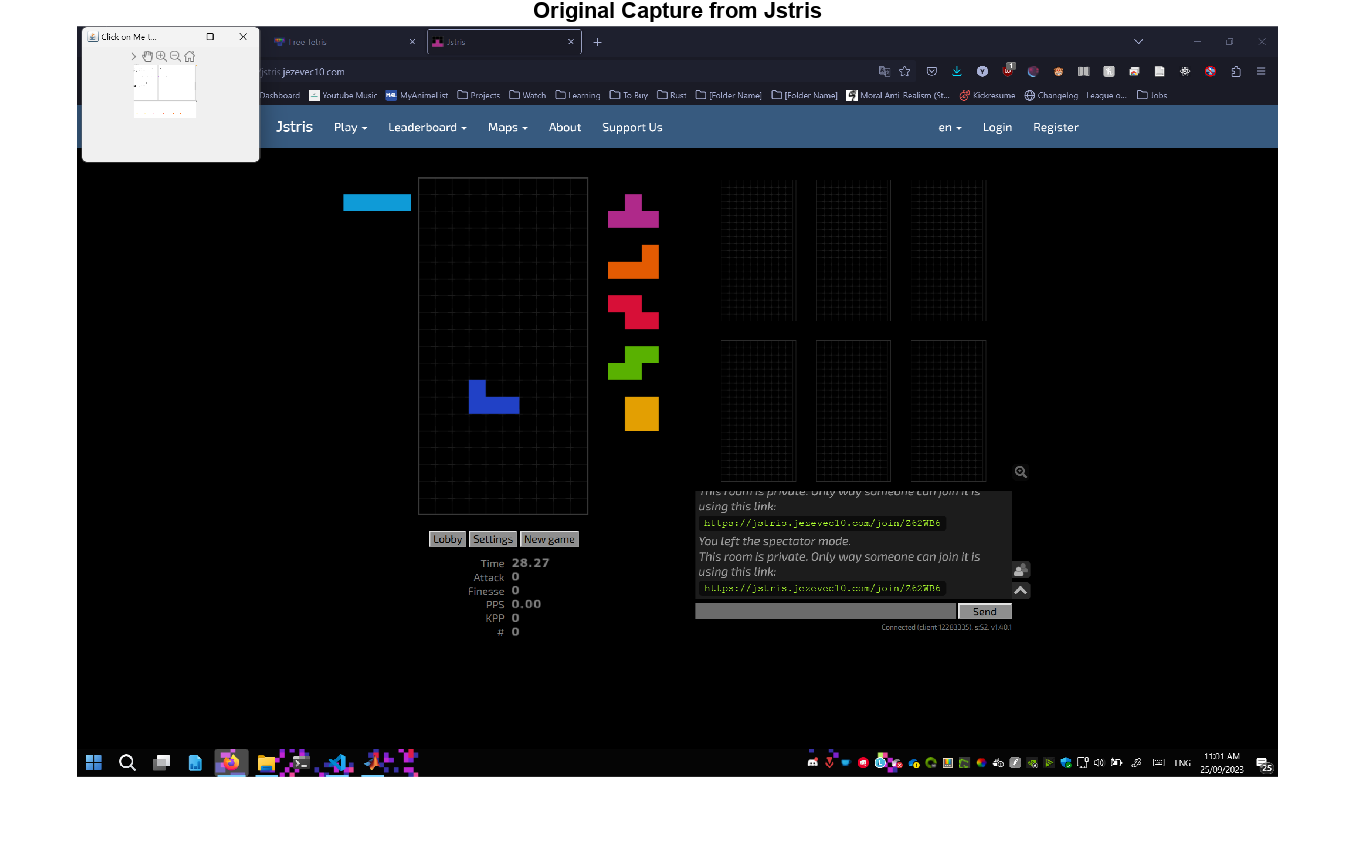

% Jstris Example
sampleImage = imread("SampleCaptures\jstris.png");
s = state(sampleImage);
s = s.updateState(sampleImage);

figure;
imshow(sampleImage)
title('Original Capture from Jstris')

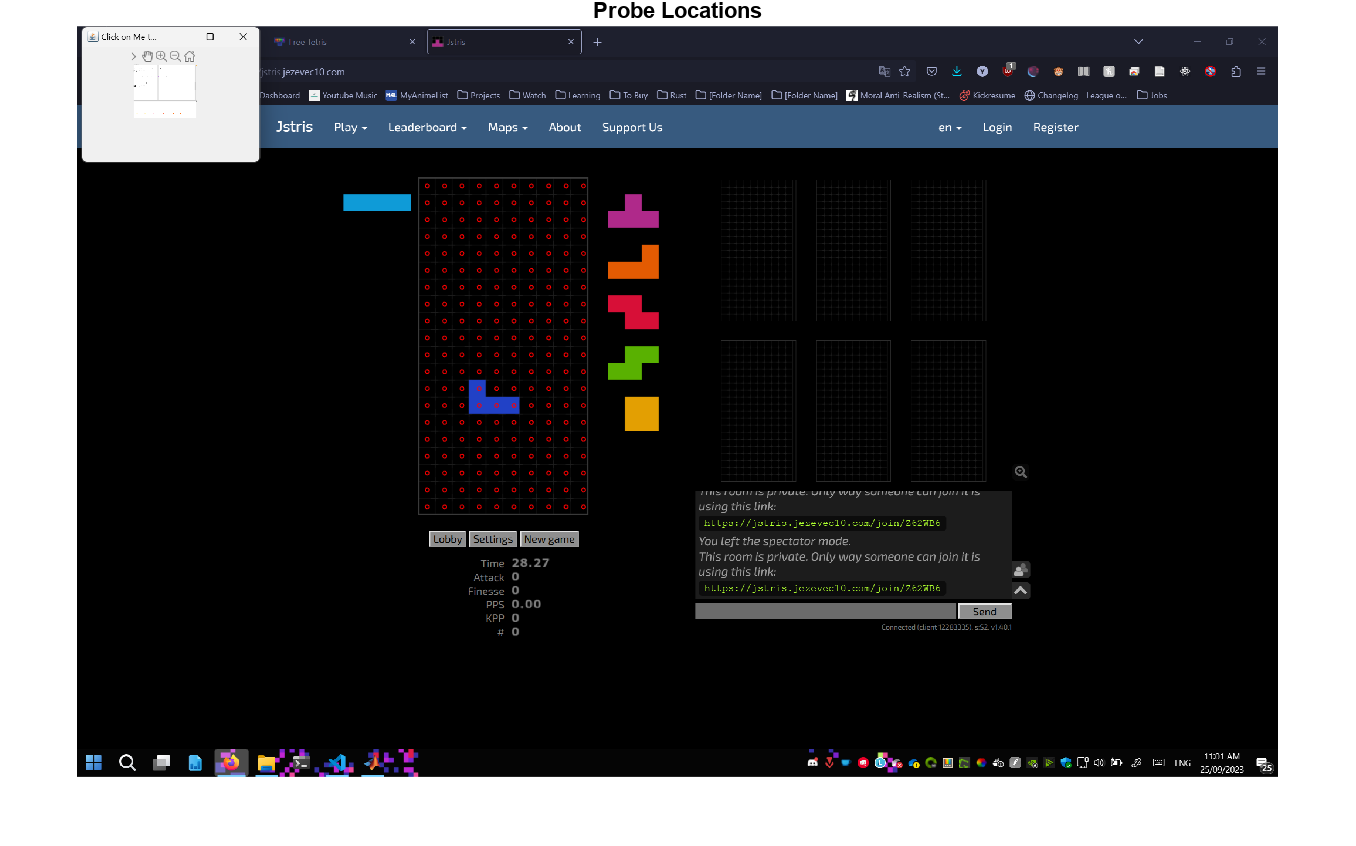

figure;
imshow(sampleImage)
hold on;
title('Probe Locations')
plot(s.probes(:,1), s.probes(:,2), 'o', 'MarkerSize', 2, 'MarkerEdgeColor', 'r')
hold off;

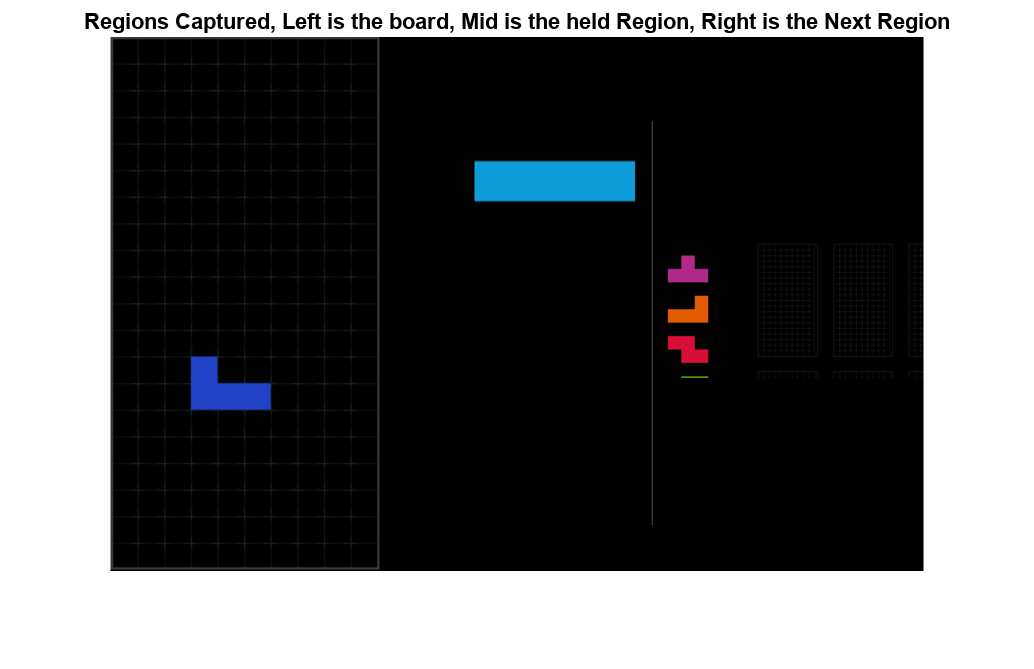

figure;
montage({
s.image(s.board(3):s.board(4), s.board(1):s.board(2), :),
s.image(s.heldRegion(1):s.heldRegion(2), s.heldRegion(3):s.heldRegion(4), :)
s.image(s.nextRegion(1):s.nextRegion(2), s.nextRegion(3):s.nextRegion(4), :)
});
title('Regions Captured, Left is the board, Mid is the held Region, Right is the Next Region')

fprintf('Piece: %s, Next: %s, Held: %s\n', s.piece, s.nextPiece, s.heldPiece);

Piece: J, Next: T, Held: I



disp("State: "); disp(s.data);

State: 
   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0



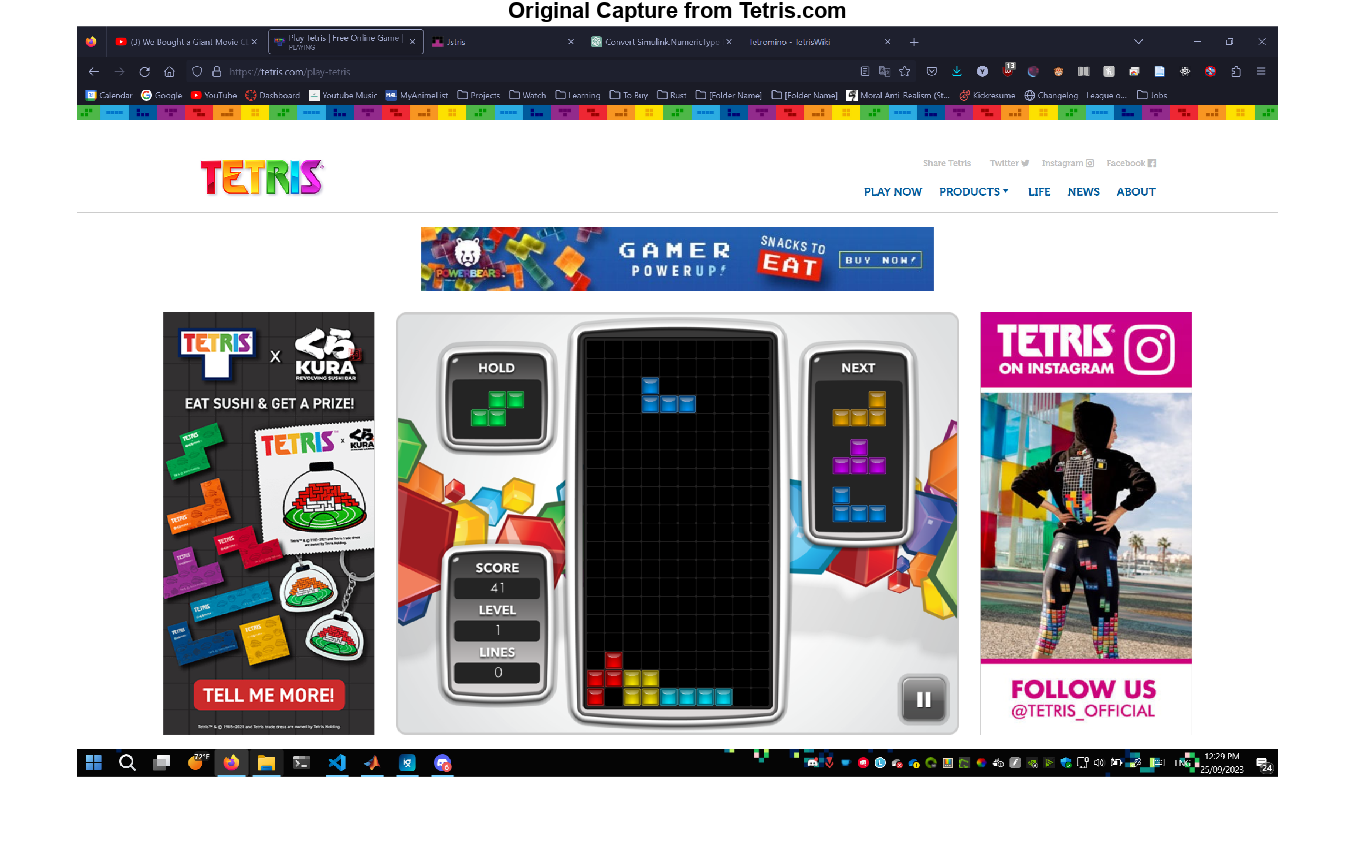

% Tetris.com Example
sampleImage = imread("SampleCaptures\tetris.png");
s = state(sampleImage);
s = s.updateState(sampleImage);

figure;
imshow(sampleImage)
title('Original Capture from Tetris.com')

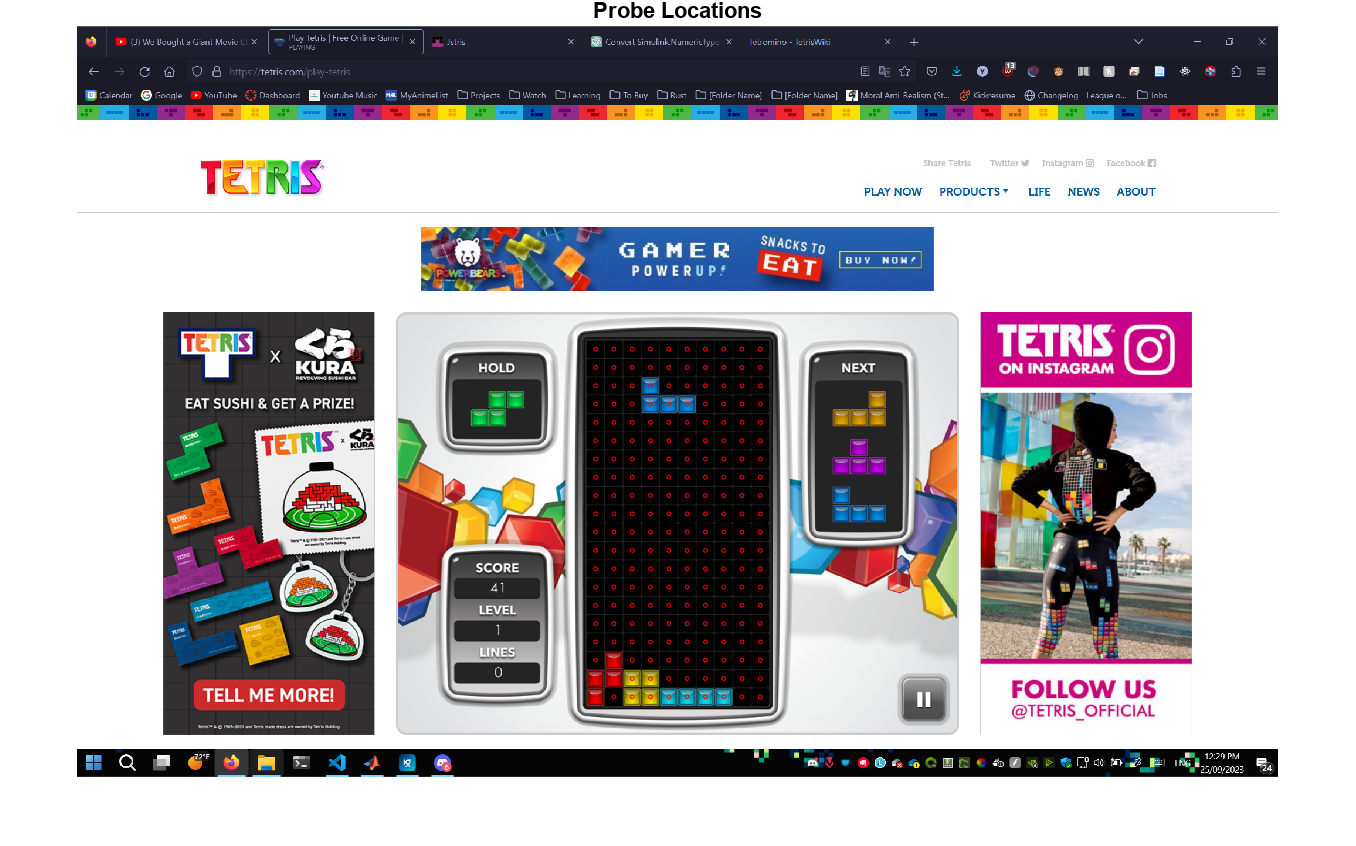

figure;
imshow(sampleImage)
hold on;
title('Probe Locations')
plot(s.probes(:,1), s.probes(:,2), 'o', 'MarkerSize', 2, 'MarkerEdgeColor', 'r')
hold off;

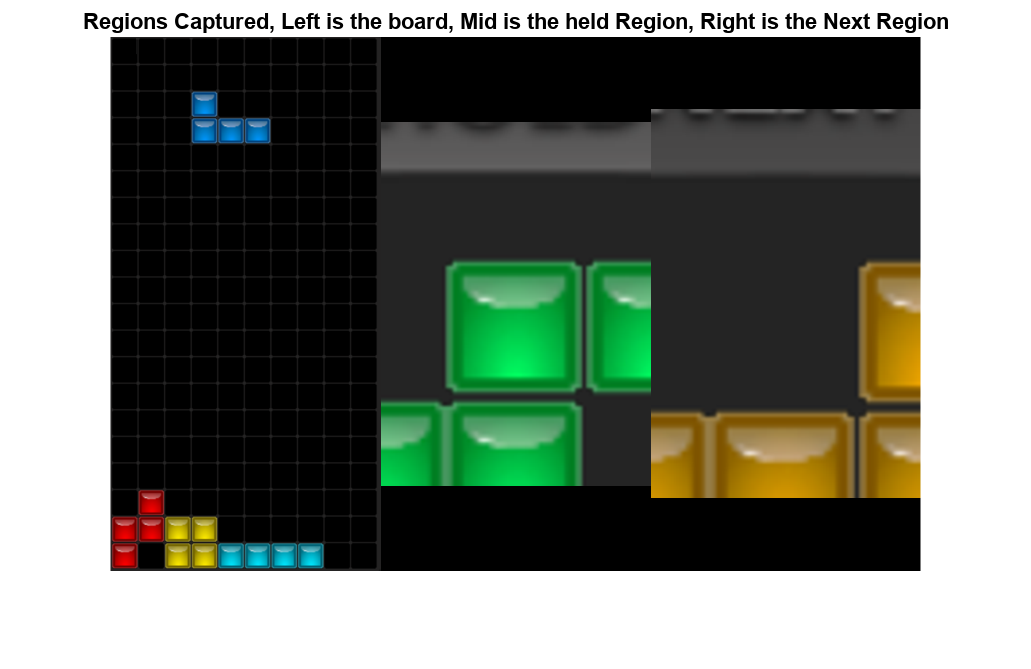

figure;
montage({
s.image(s.board(3):s.board(4), s.board(1):s.board(2), :),
s.image(s.heldRegion(1):s.heldRegion(2), s.heldRegion(3):s.heldRegion(4), :)
s.image(s.nextRegion(1):s.nextRegion(2), s.nextRegion(3):s.nextRegion(4), :)
});
title('Regions Captured, Left is the board, Mid is the held Region, Right is the Next Region')

fprintf('Piece: %s, Next: %s, Held: %s\n', s.piece, s.nextPiece, s.heldPiece);

Piece: J, Next: L, Held: S



disp("State: "); disp(s.data);

State: 
   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0
   0   1   0   0   0   0   0   0   0   0
   1   1   1   1   0   0   0   0   0   0
   1   0   1   1   1   1   1   1   0   0



   1   5   1
   2   5   1
   3   4   1
   4   4   1
   5   3   1
   6   3   1
   7   3   1
   8   3   1
   1   5   2
   2   6   2
   3   5   2
   4   5   2
   5   4   2
   6   4   2
   7   4   2
   8   4   2
   9   3   2
   1   4   3
   2   4   3
   3   3   3
   4   3   3
   5   3   3
   6   3   3
   7   2   3
   8   2   3
   1   6   4
   2   6   4
   3   5   4
   4   5   4
   5   4   4
   6   4   4
   7   4   4
   8   4   4
   9   3   4



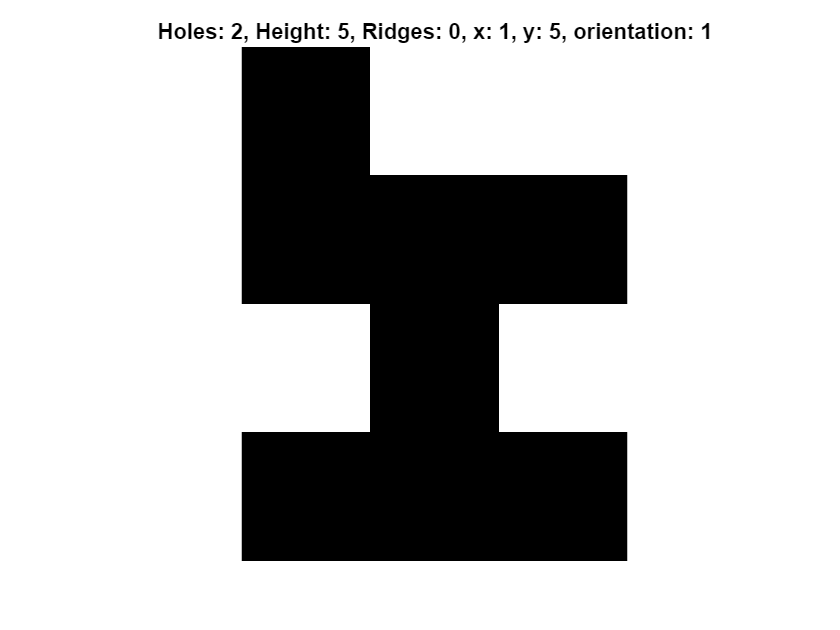

   2   3   2   2   1   1   1   1   0   0

   5   4   4   2   1   1   1   1   0   0



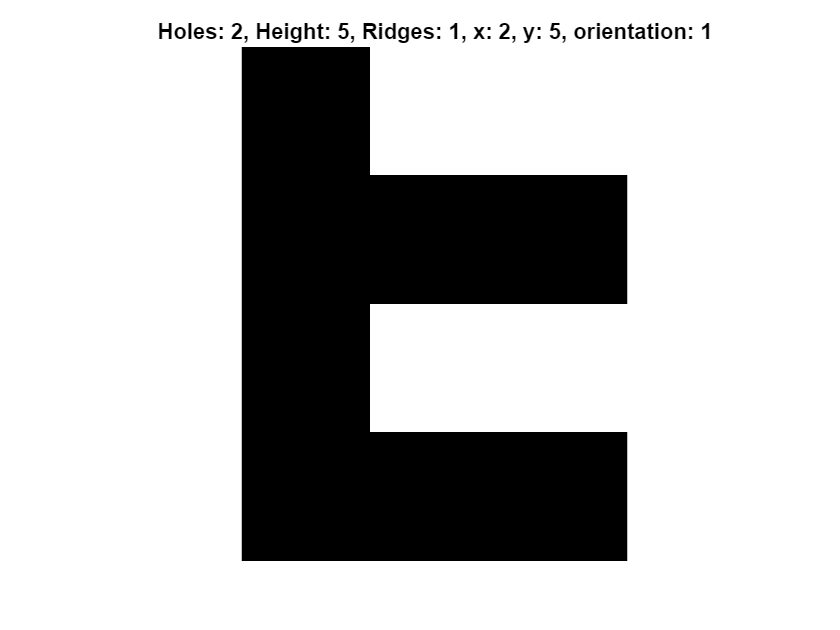

   2   3   2   2   1   1   1   1   0   0

   2   5   4   4   1   1   1   1   0   0



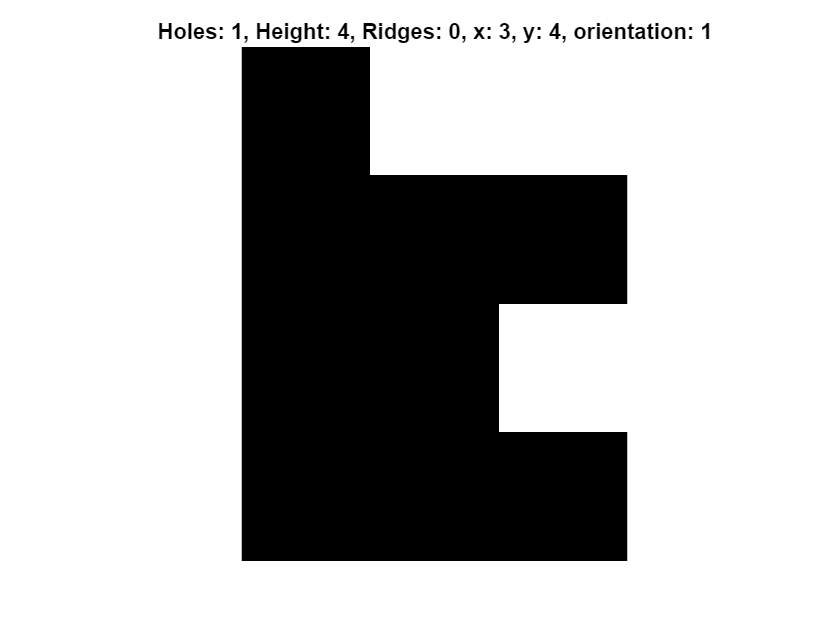

   2   3   2   2   1   1   1   1   0   0

   2   3   4   3   3   1   1   1   0   0



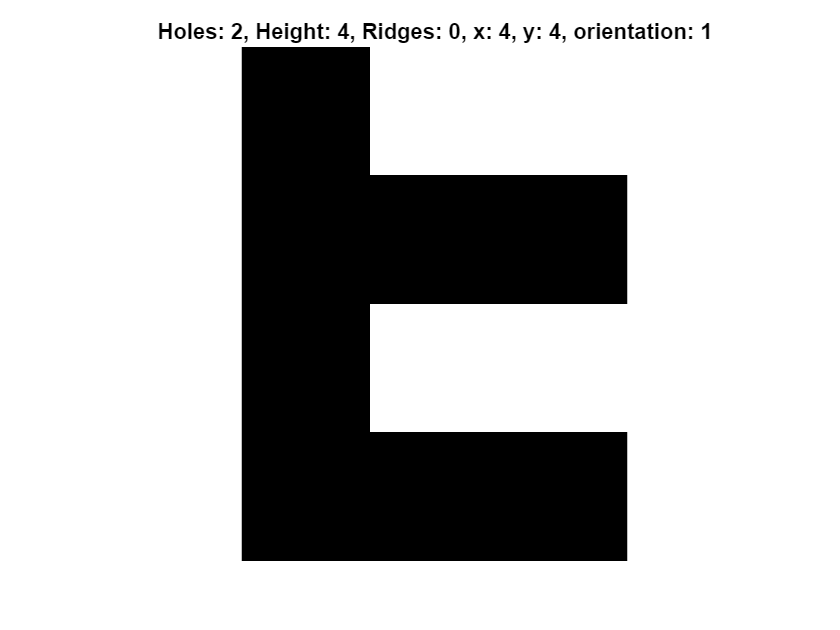

   2   3   2   2   1   1   1   1   0   0

   2   3   2   4   3   3   1   1   0   0



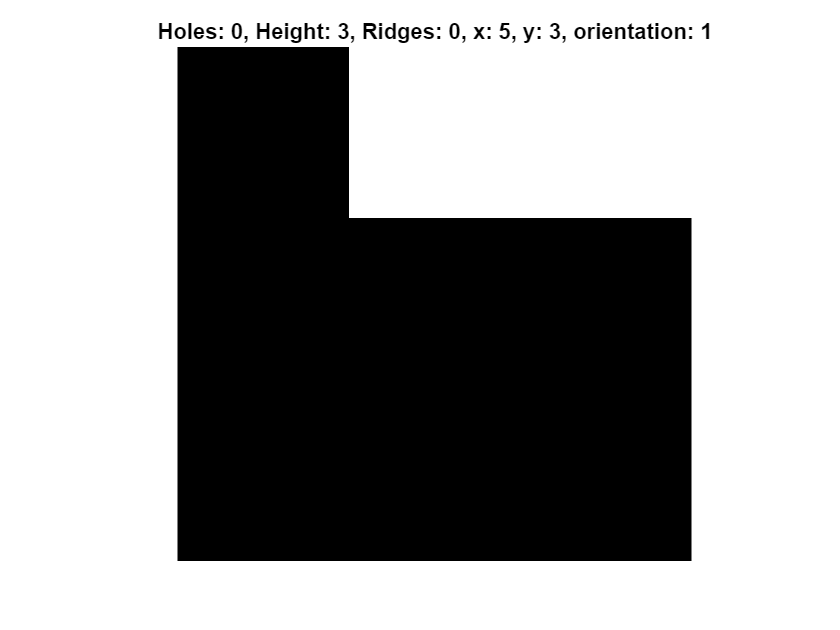

   2   3   2   2   1   1   1   1   0   0

   2   3   2   2   3   2   2   1   0   0



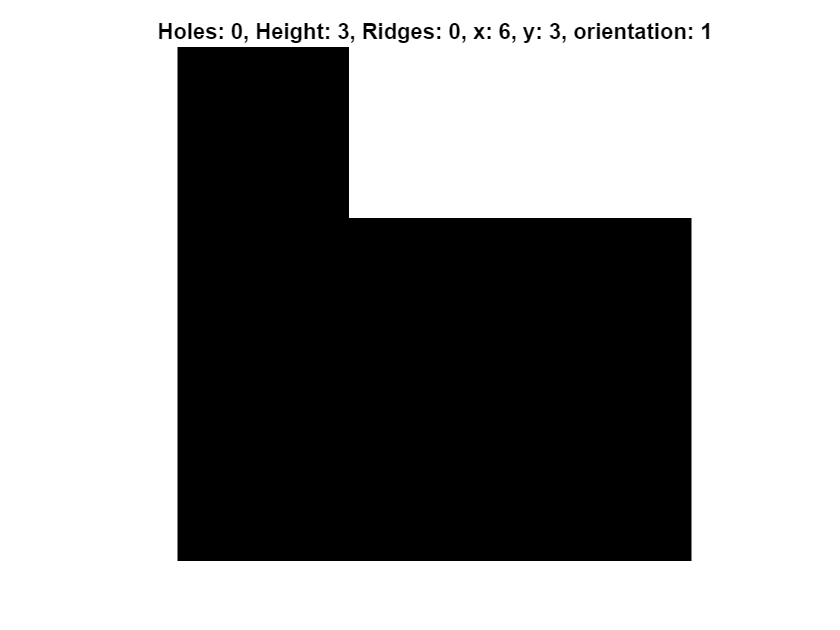

   2   3   2   2   1   1   1   1   0   0

   2   3   2   2   1   3   2   2   0   0



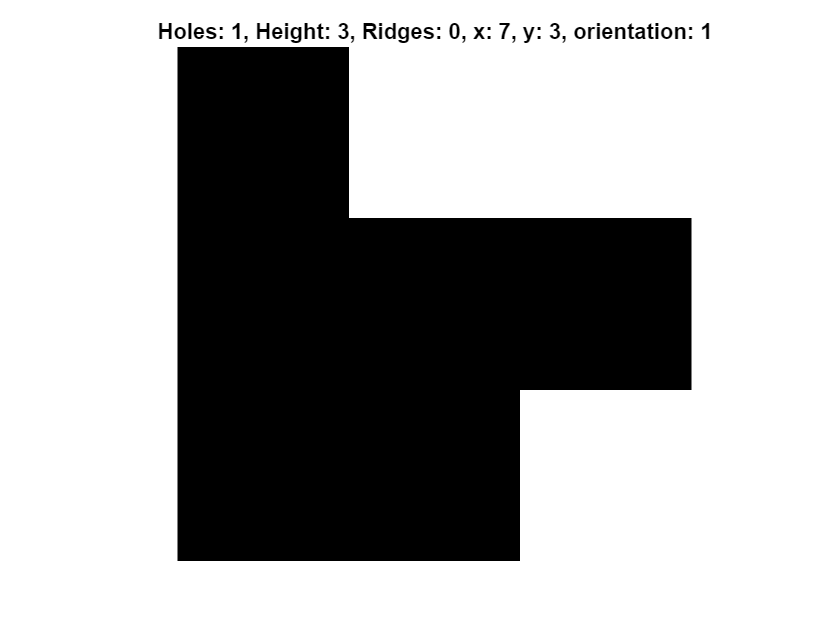

   2   3   2   2   1   1   1   1   0   0

   2   3   2   2   1   1   3   2   2   0



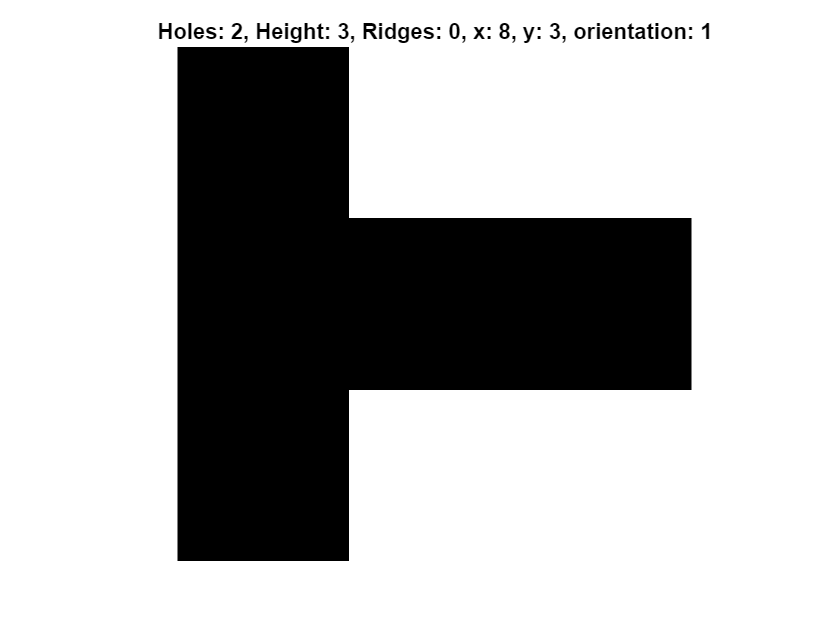

   2   3   2   2   1   1   1   1   0   0

   2   3   2   2   1   1   1   3   2   2



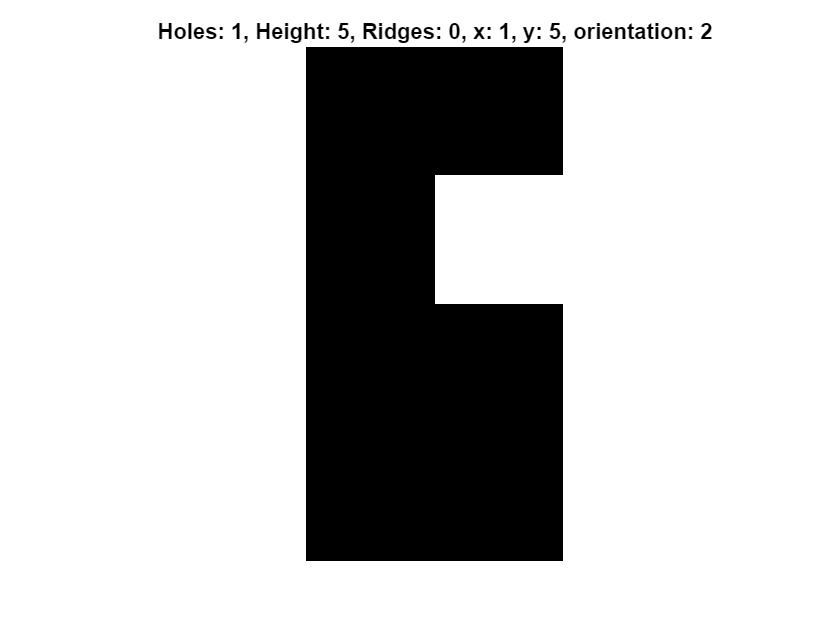

   2   3   2   2   1   1   1   1   0   0

   5   5   2   2   1   1   1   1   0   0



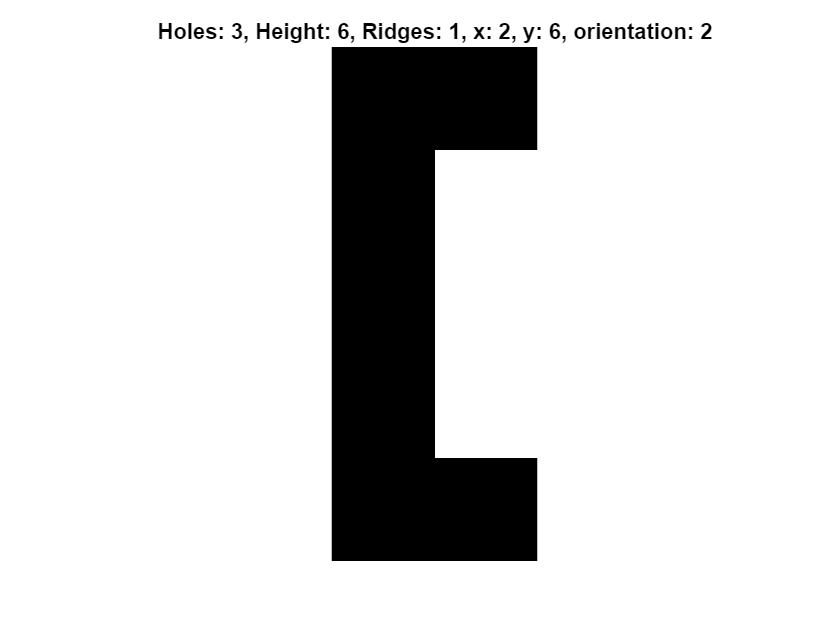

   2   3   2   2   1   1   1   1   0   0

   2   6   6   2   1   1   1   1   0   0



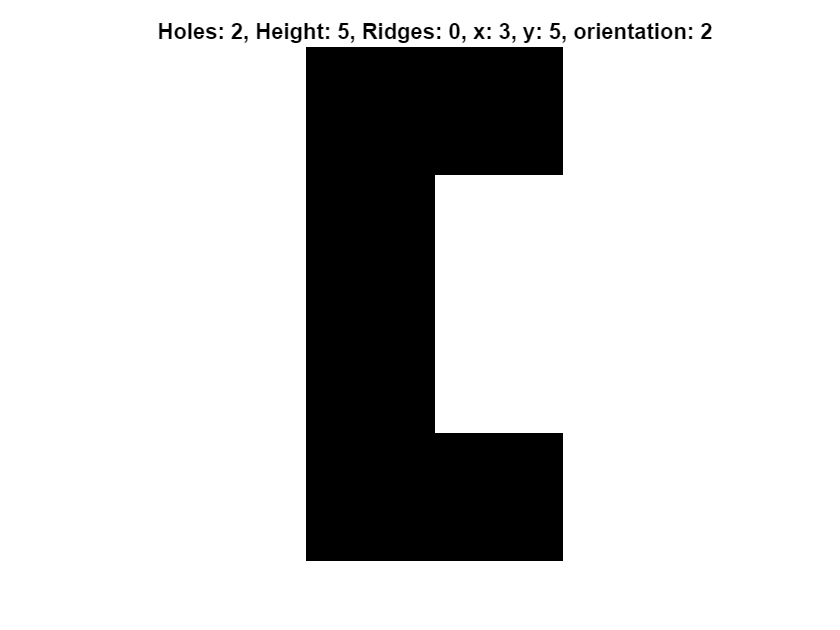

   2   3   2   2   1   1   1   1   0   0

   2   3   5   5   1   1   1   1   0   0



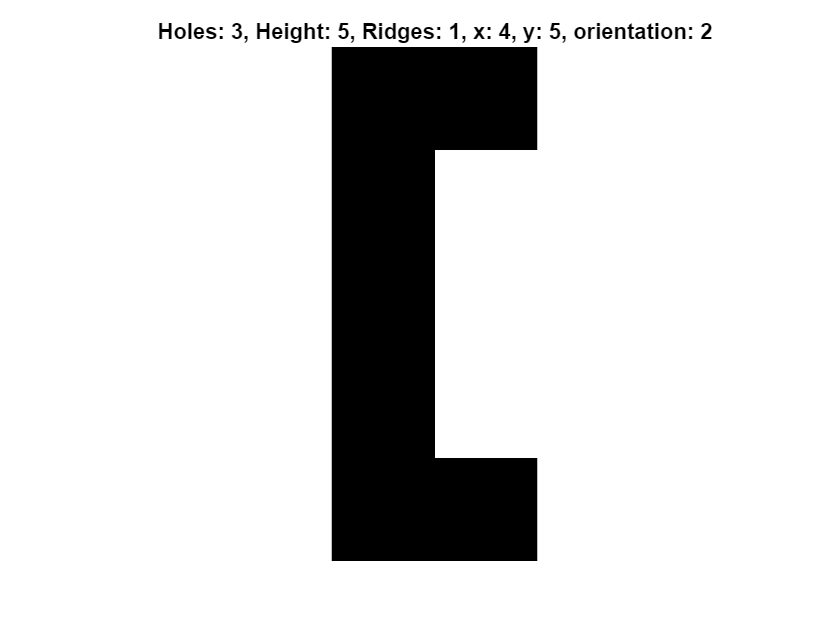

   2   3   2   2   1   1   1   1   0   0

   2   3   2   5   5   1   1   1   0   0



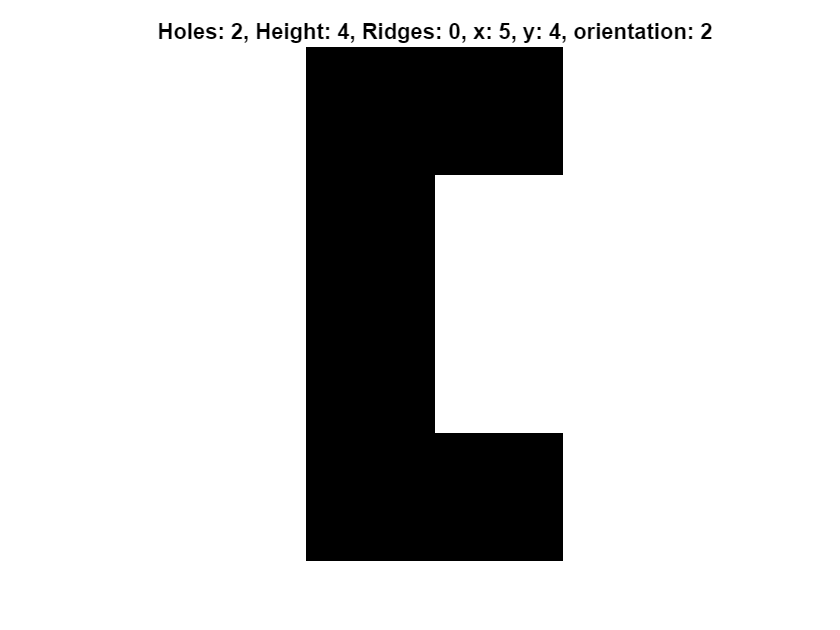

   2   3   2   2   1   1   1   1   0   0

   2   3   2   2   4   4   1   1   0   0



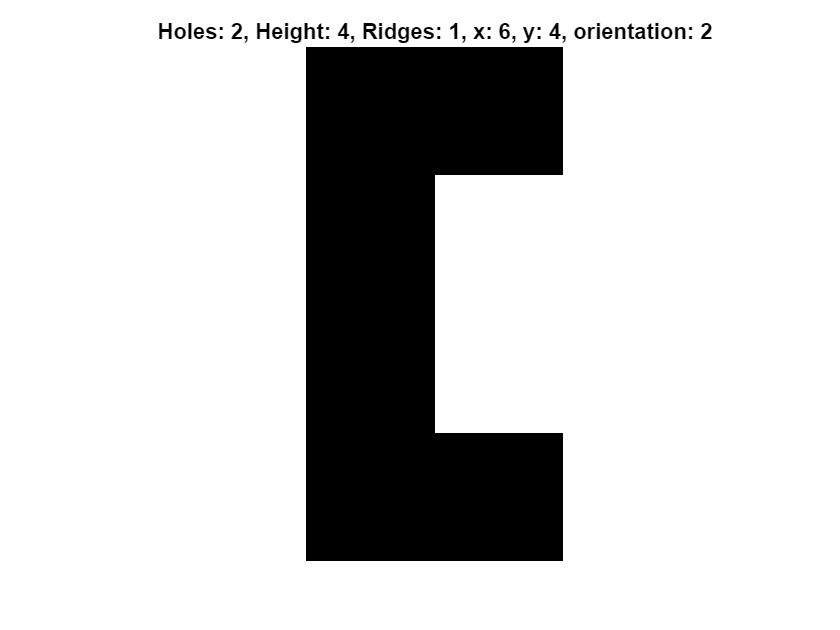

   2   3   2   2   1   1   1   1   0   0

   2   3   2   2   1   4   4   1   0   0



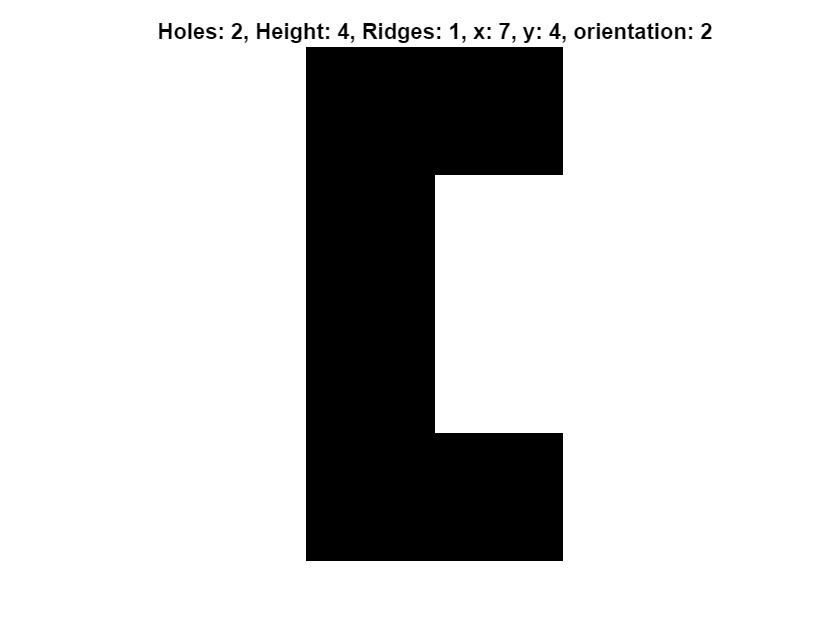

   2   3   2   2   1   1   1   1   0   0

   2   3   2   2   1   1   4   4   0   0



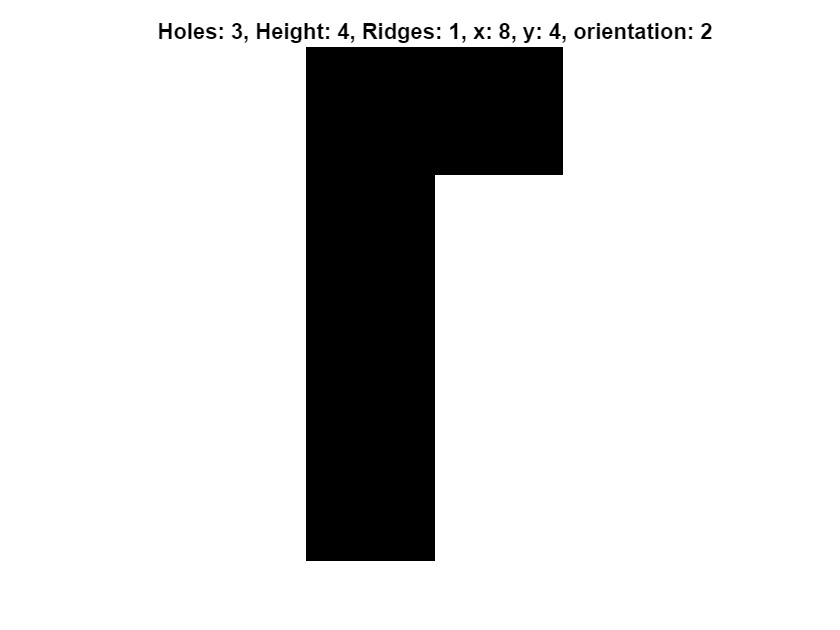

   2   3   2   2   1   1   1   1   0   0

   2   3   2   2   1   1   1   4   4   0



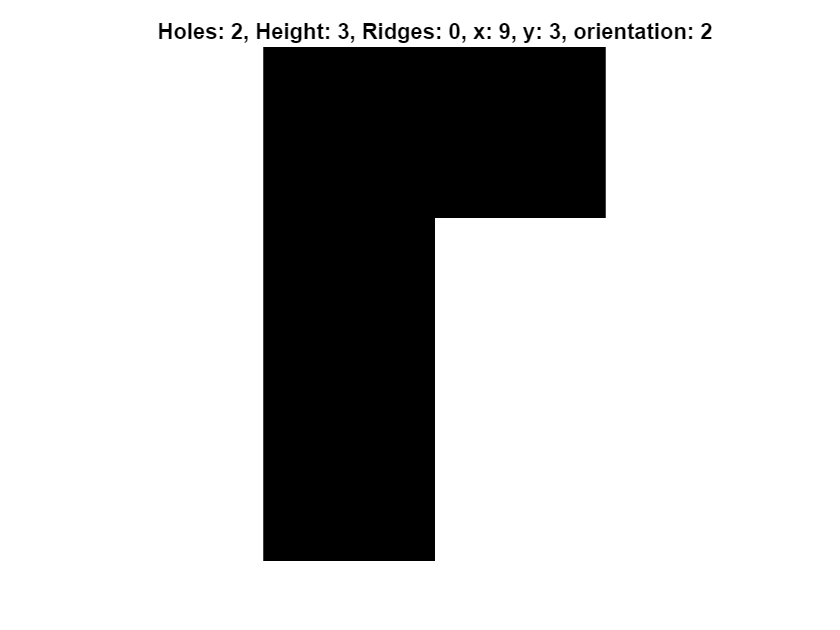

   2   3   2   2   1   1   1   1   0   0

   2   3   2   2   1   1   1   1   3   3



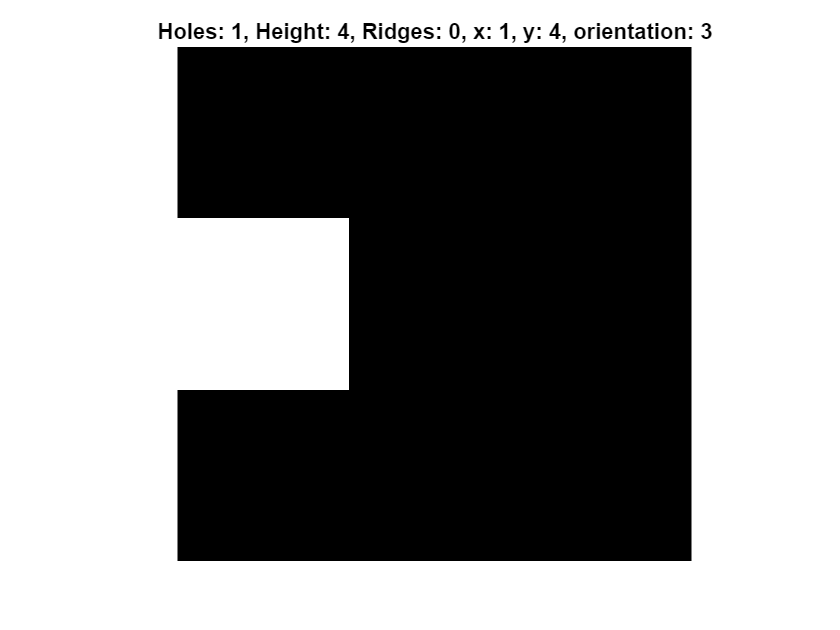

   2   3   2   2   1   1   1   1   0   0

   4   4   4   2   1   1   1   1   0   0



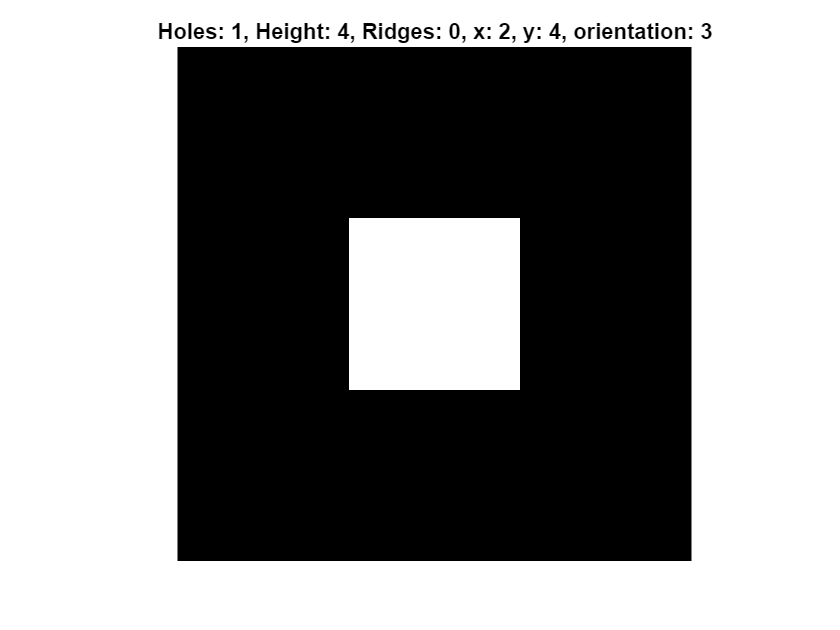

   2   3   2   2   1   1   1   1   0   0

   2   4   4   4   1   1   1   1   0   0



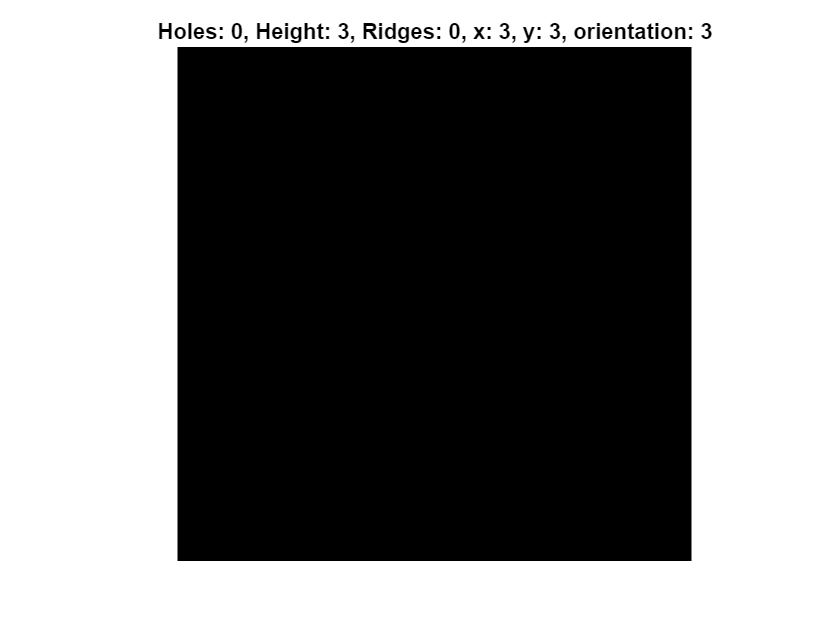

   2   3   2   2   1   1   1   1   0   0

   2   3   3   3   3   1   1   1   0   0



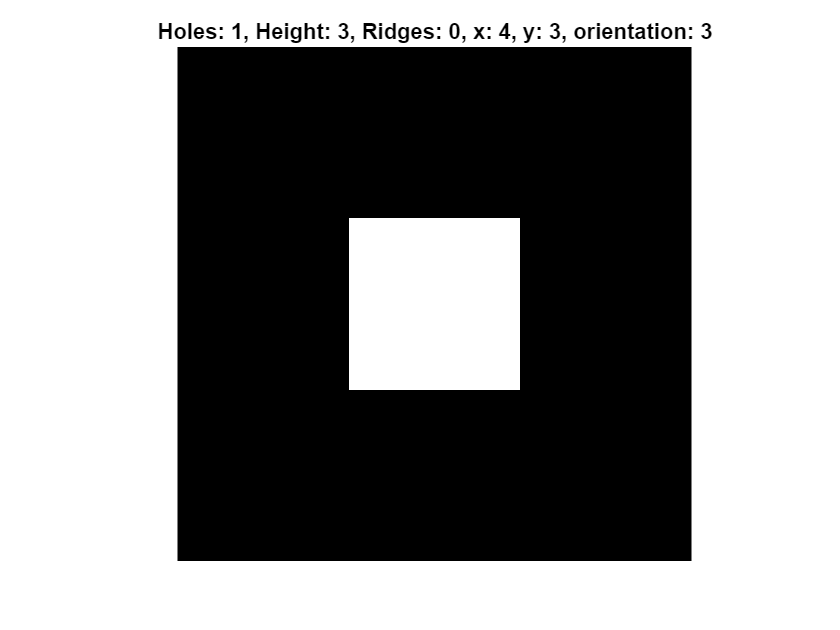

   2   3   2   2   1   1   1   1   0   0

   2   3   2   3   3   3   1   1   0   0



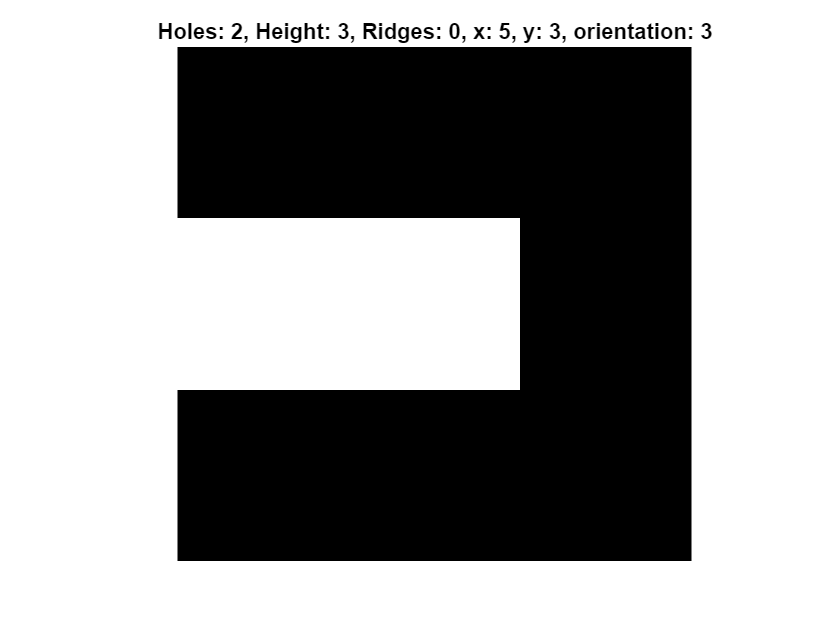

   2   3   2   2   1   1   1   1   0   0

   2   3   2   2   3   3   3   1   0   0



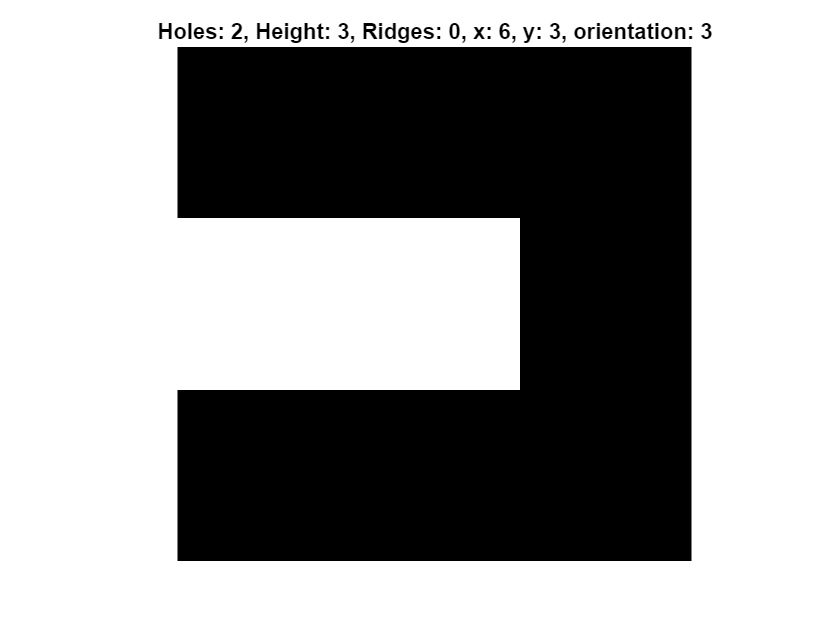

   2   3   2   2   1   1   1   1   0   0

   2   3   2   2   1   3   3   3   0   0



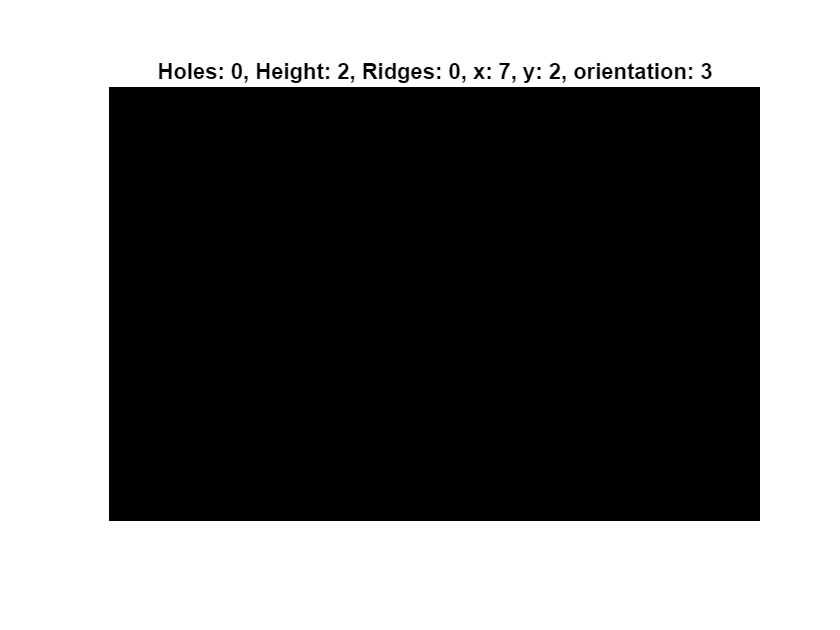

   2   3   2   2   1   1   1   1   0   0

   2   3   2   2   1   1   2   2   2   0



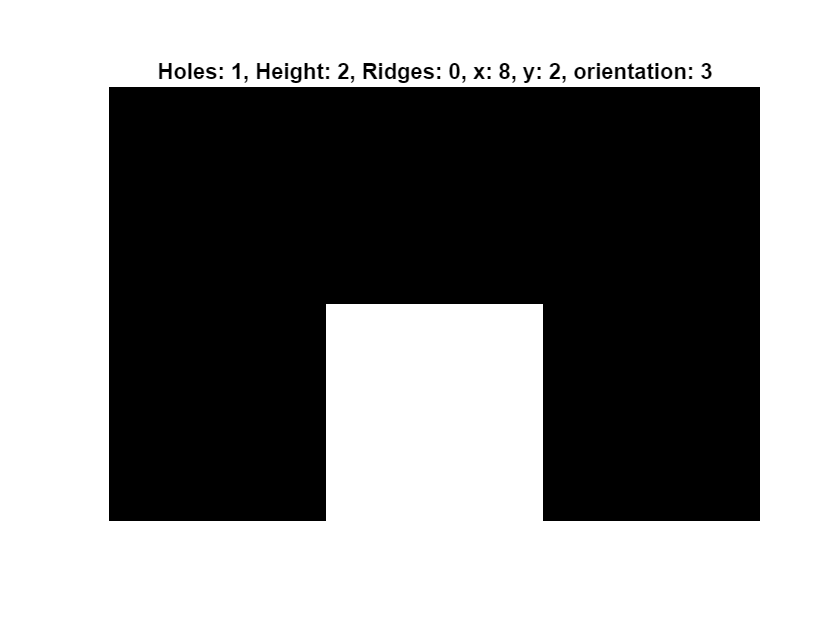

   2   3   2   2   1   1   1   1   0   0

   2   3   2   2   1   1   1   2   2   2



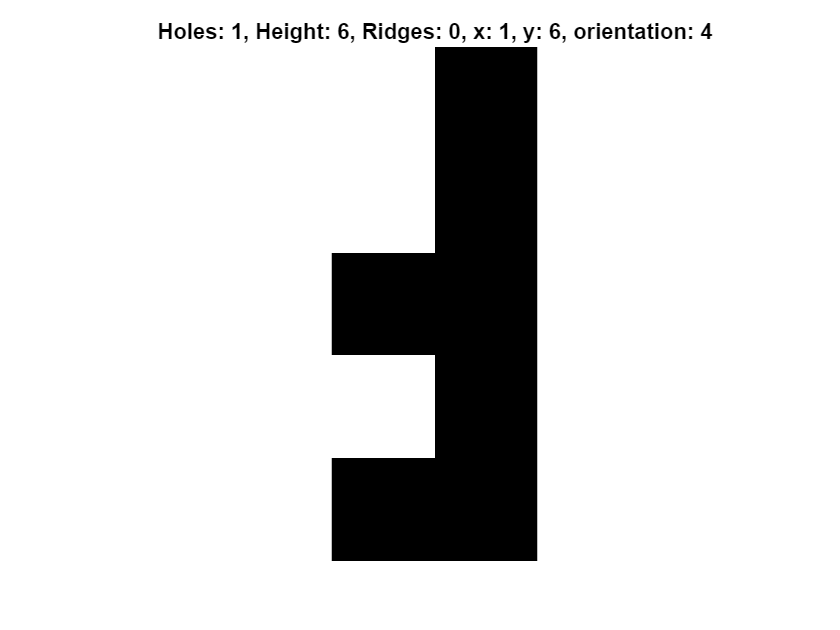

   2   3   2   2   1   1   1   1   0   0

   4   6   2   2   1   1   1   1   0   0



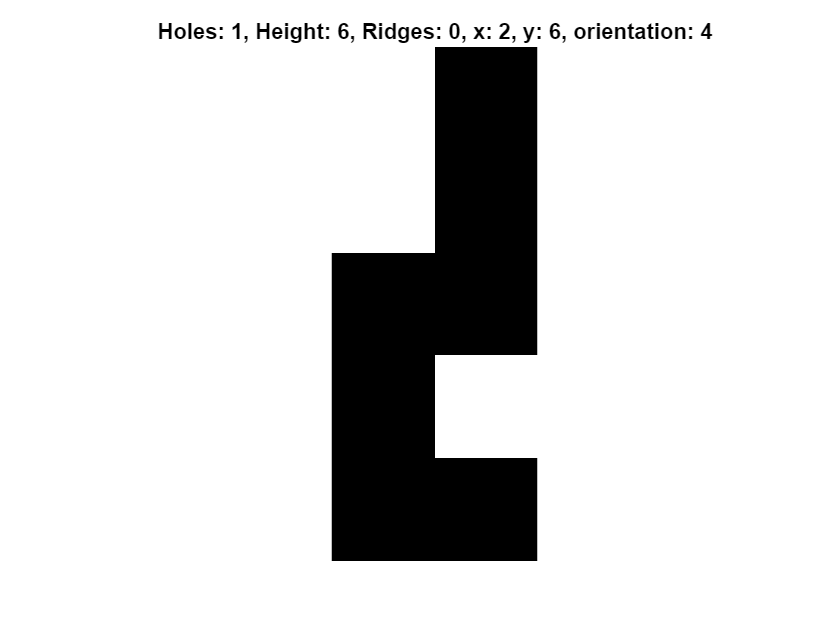

   2   3   2   2   1   1   1   1   0   0

   2   4   6   2   1   1   1   1   0   0



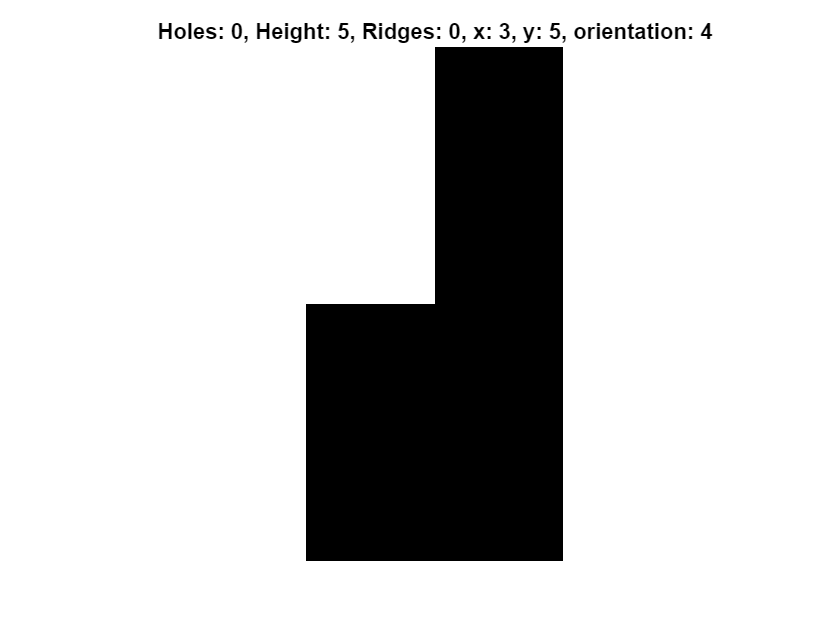

   2   3   2   2   1   1   1   1   0   0

   2   3   3   5   1   1   1   1   0   0



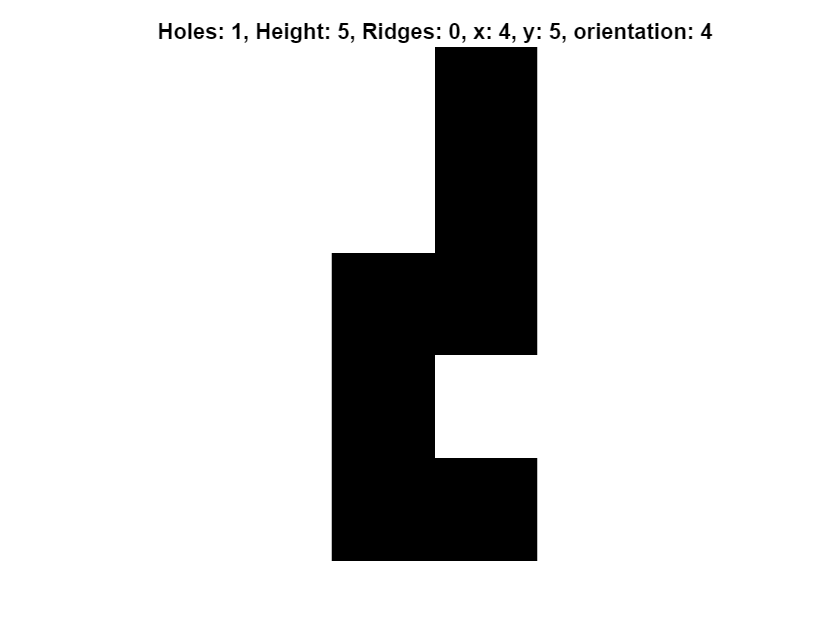

   2   3   2   2   1   1   1   1   0   0

   2   3   2   3   5   1   1   1   0   0



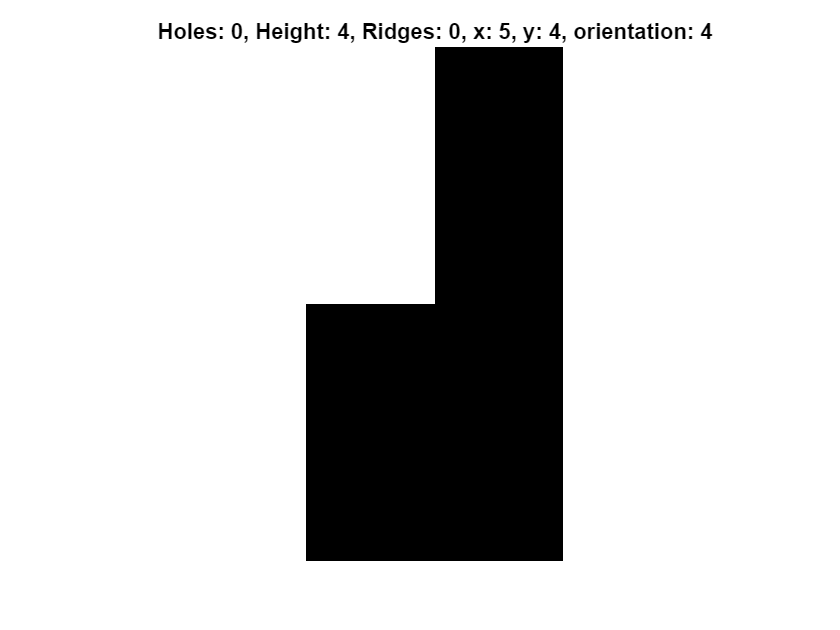

   2   3   2   2   1   1   1   1   0   0

   2   3   2   2   2   4   1   1   0   0



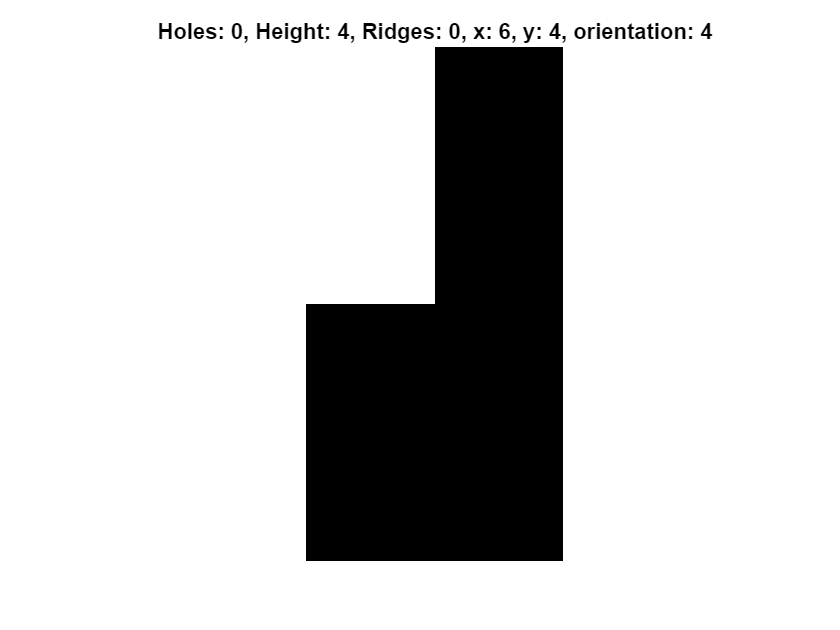

   2   3   2   2   1   1   1   1   0   0

   2   3   2   2   1   2   4   1   0   0



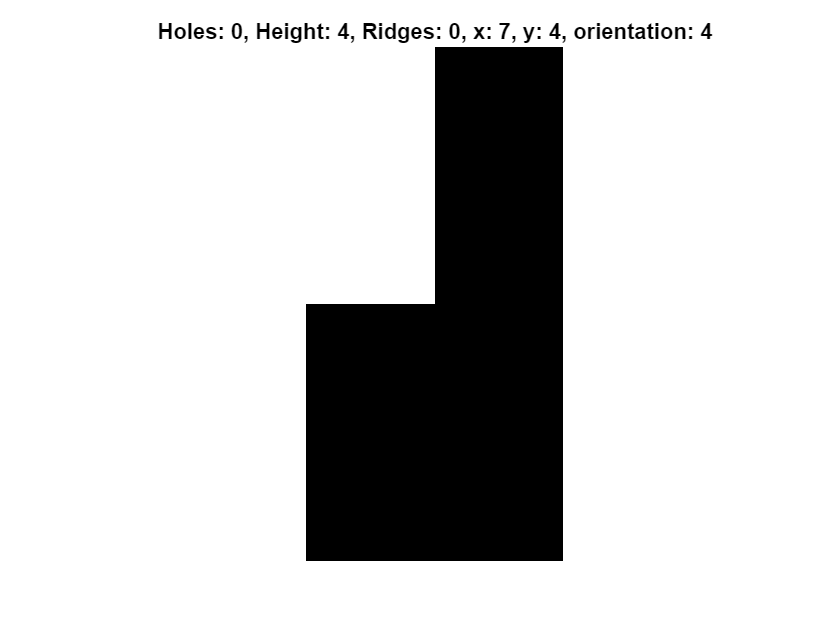

   2   3   2   2   1   1   1   1   0   0

   2   3   2   2   1   1   2   4   0   0



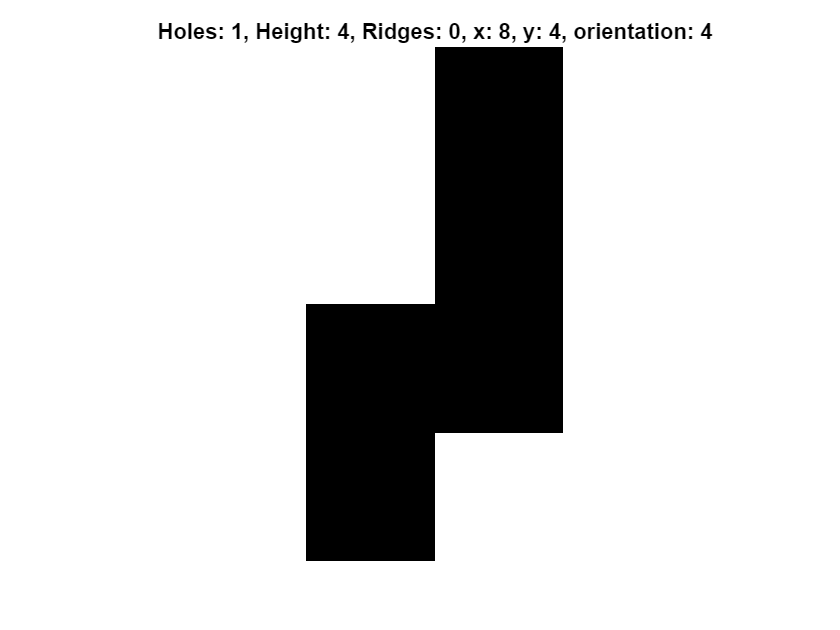

   2   3   2   2   1   1   1   1   0   0

   2   3   2   2   1   1   1   2   4   0



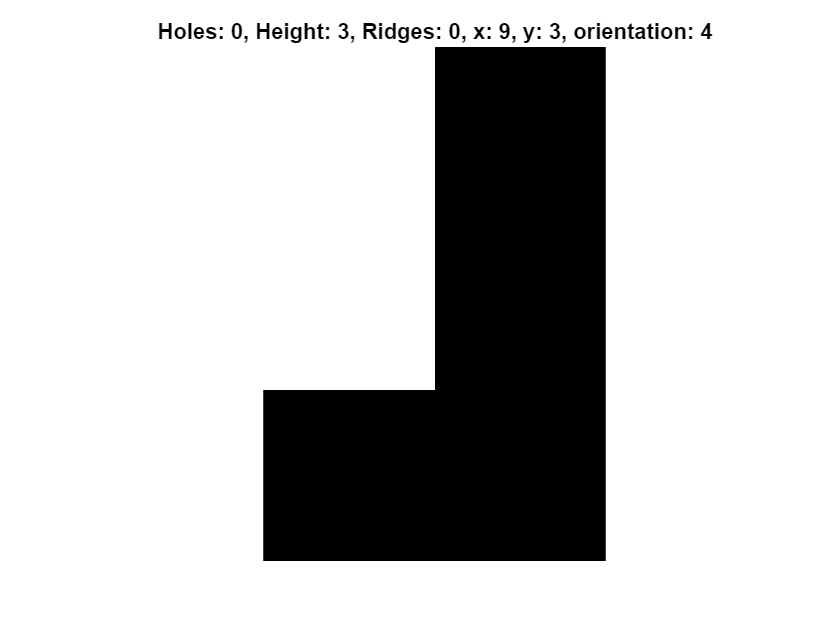

   2   3   2   2   1   1   1   1   0   0

   2   3   2   2   1   1   1   1   1   3

   1   5   1
   2   5   1
   3   4   1
   4   4   1
   5   3   1
   6   3   1
   7   3   1
   8   3   1
   1   6   2
   2   5   2
   3   5   2
   4   4   2
   5   4   2
   6   4   2
   7   4   2
   8   3   2
   9   3   2



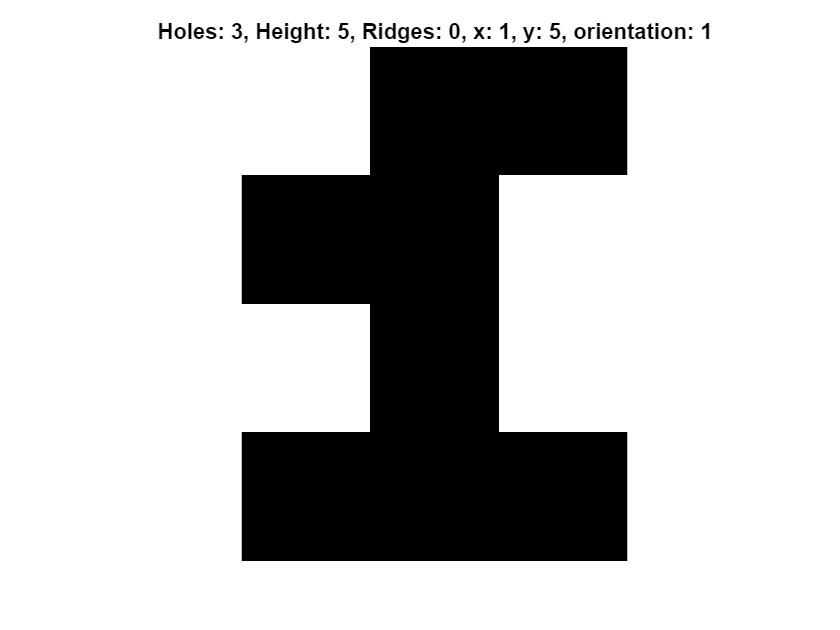

   2   3   2   2   1   1   1   1   0   0

   4   5   5   2   1   1   1   1   0   0



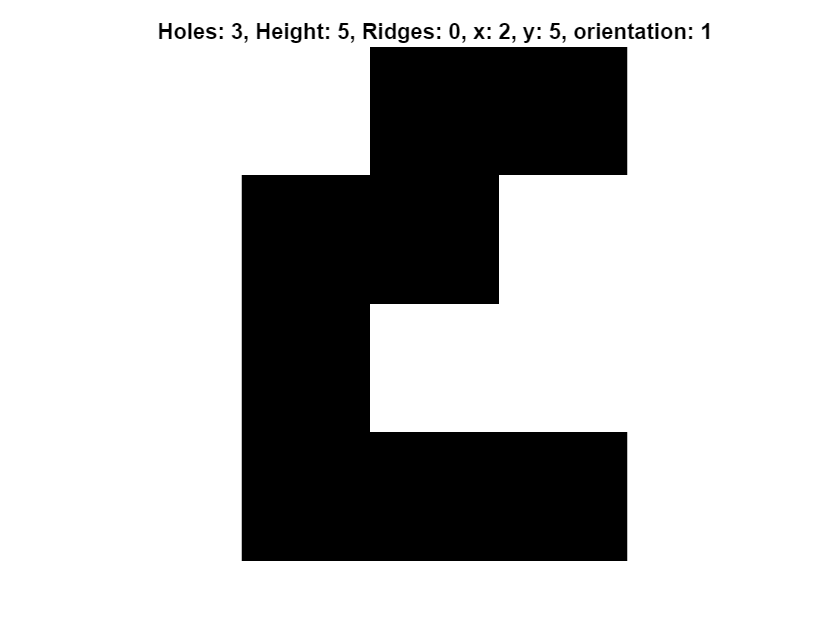

   2   3   2   2   1   1   1   1   0   0

   2   4   5   5   1   1   1   1   0   0



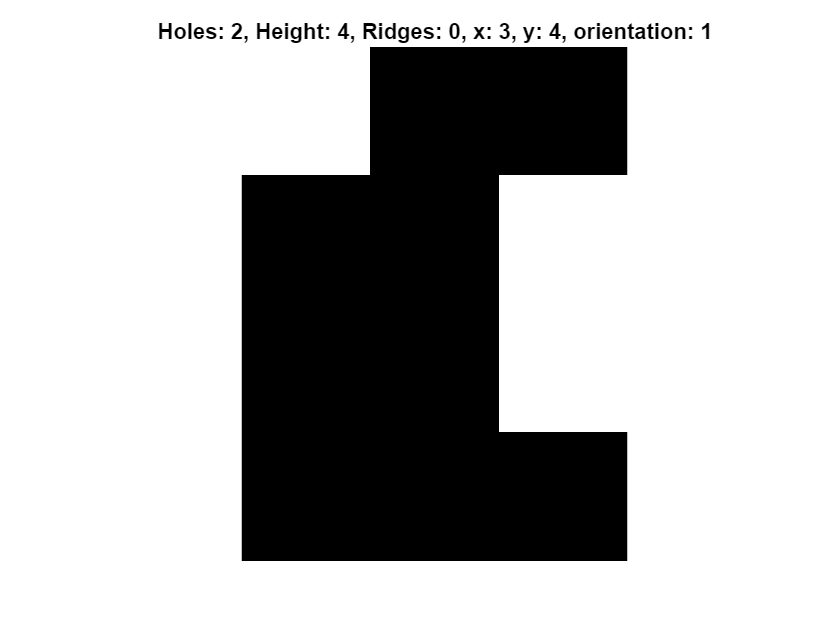

   2   3   2   2   1   1   1   1   0   0

   2   3   3   4   4   1   1   1   0   0



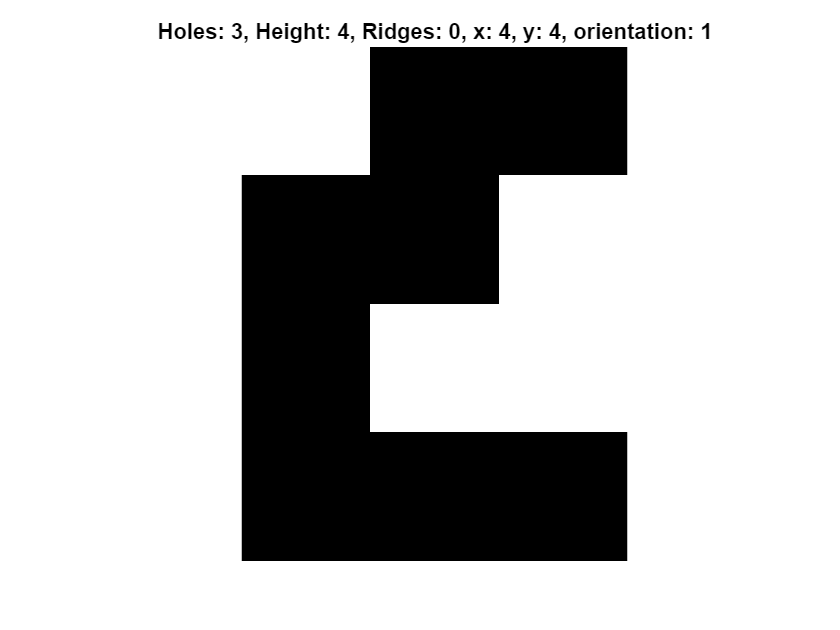

   2   3   2   2   1   1   1   1   0   0

   2   3   2   3   4   4   1   1   0   0



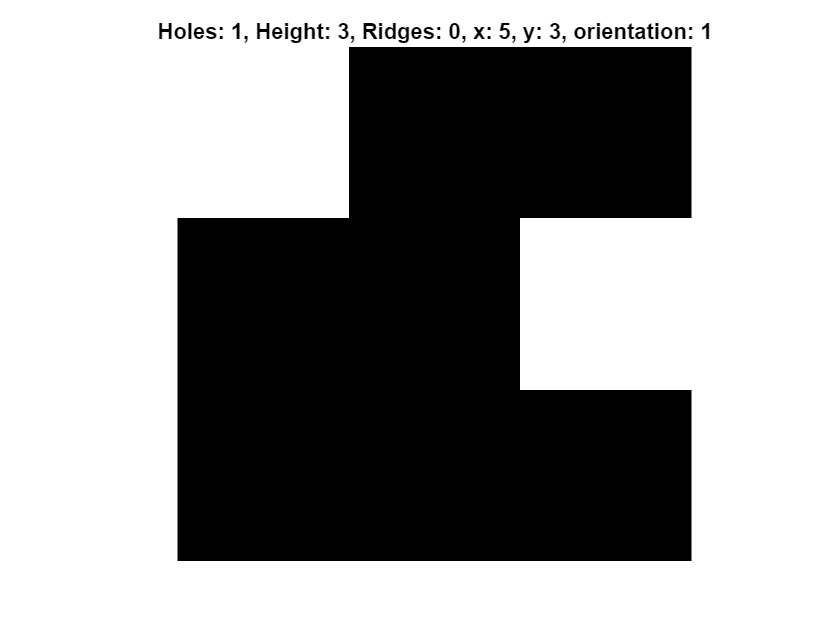

   2   3   2   2   1   1   1   1   0   0

   2   3   2   2   2   3   3   1   0   0



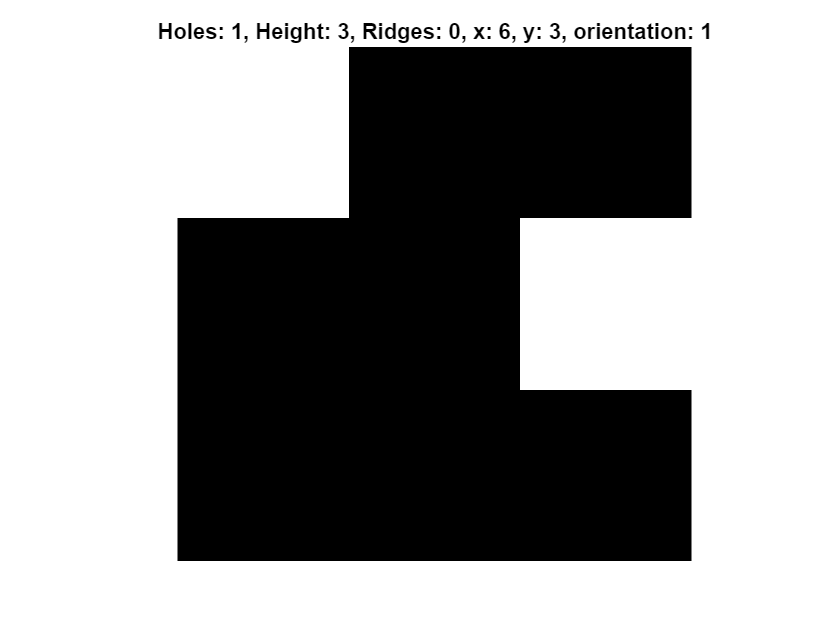

   2   3   2   2   1   1   1   1   0   0

   2   3   2   2   1   2   3   3   0   0



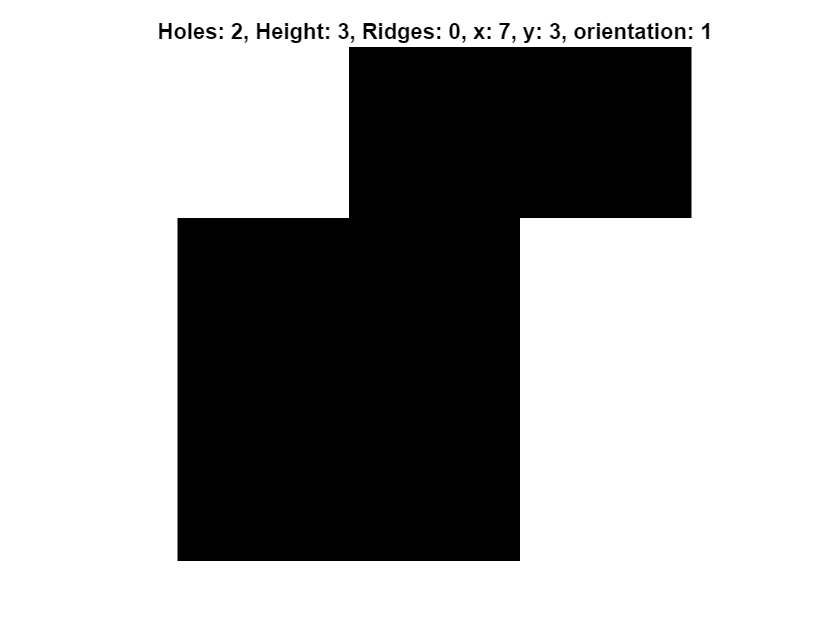

   2   3   2   2   1   1   1   1   0   0

   2   3   2   2   1   1   2   3   3   0



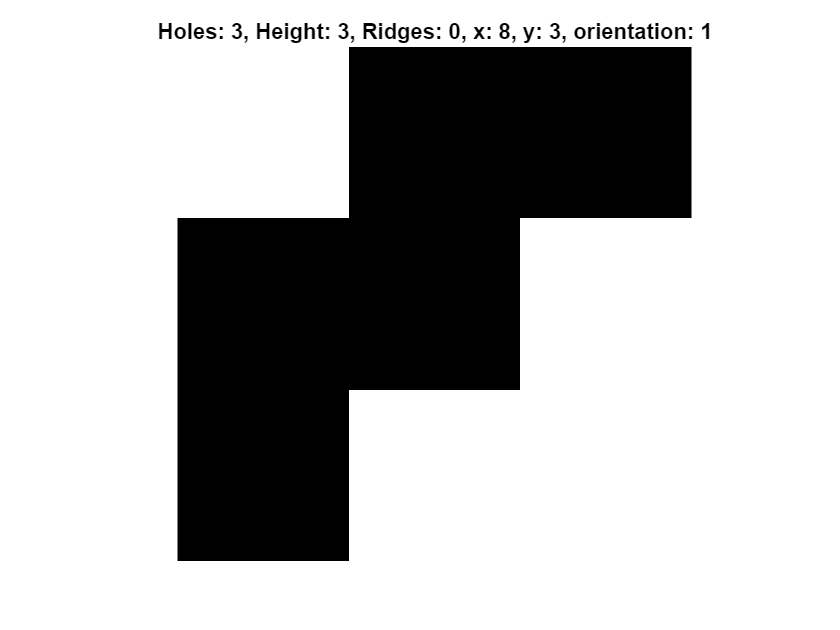

   2   3   2   2   1   1   1   1   0   0

   2   3   2   2   1   1   1   2   3   3



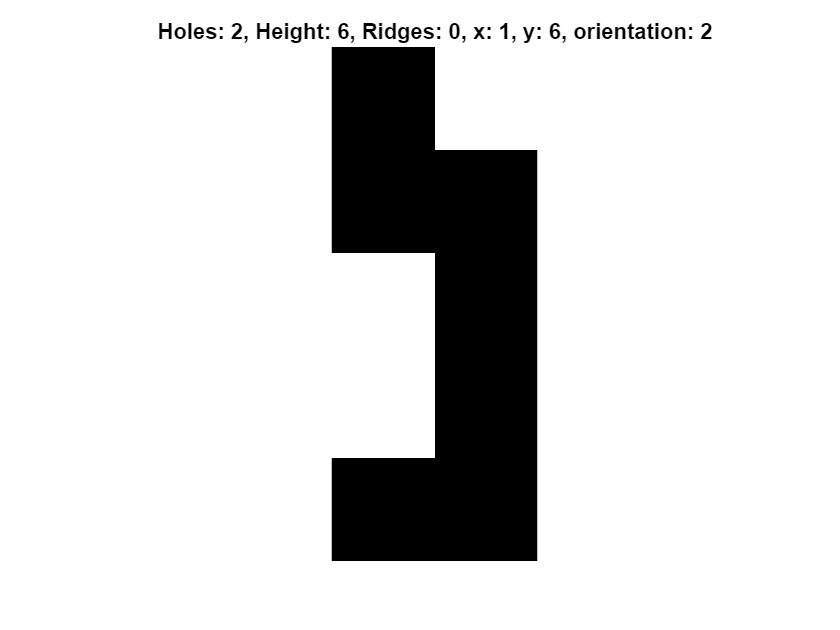

   2   3   2   2   1   1   1   1   0   0

   6   5   2   2   1   1   1   1   0   0



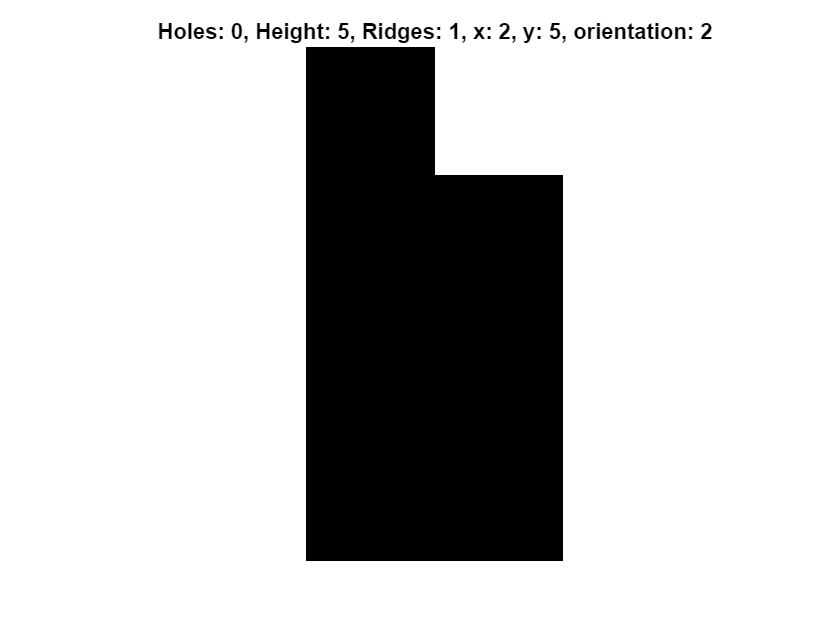

   2   3   2   2   1   1   1   1   0   0

   2   5   4   2   1   1   1   1   0   0



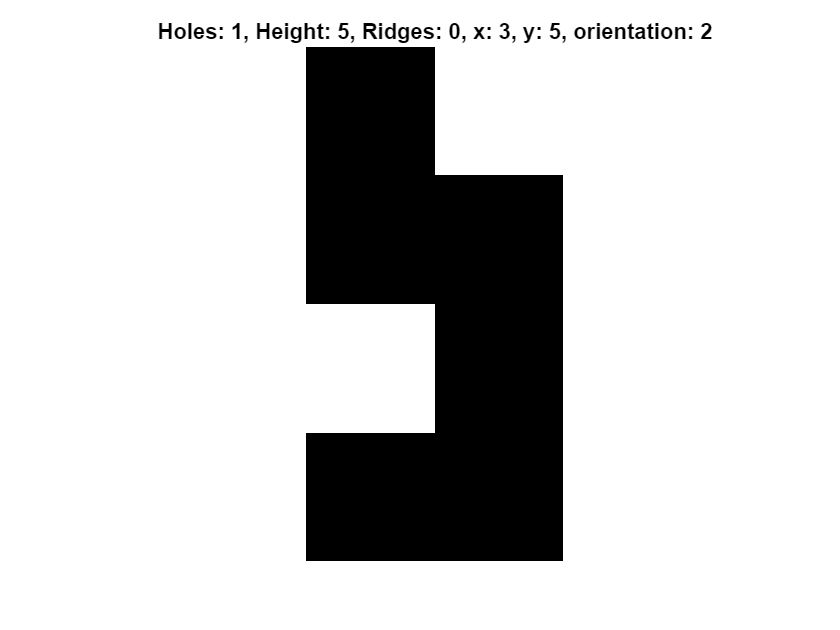

   2   3   2   2   1   1   1   1   0   0

   2   3   5   4   1   1   1   1   0   0



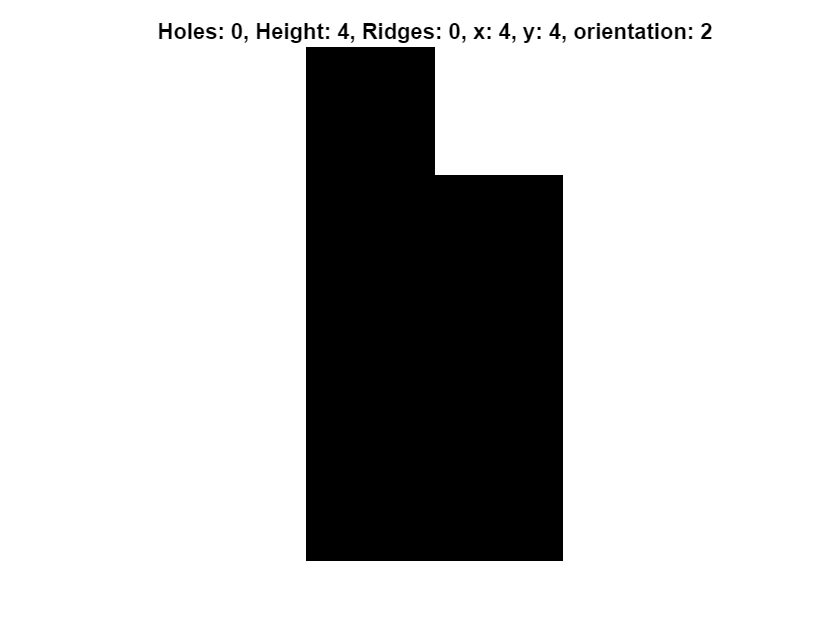

   2   3   2   2   1   1   1   1   0   0

   2   3   2   4   3   1   1   1   0   0



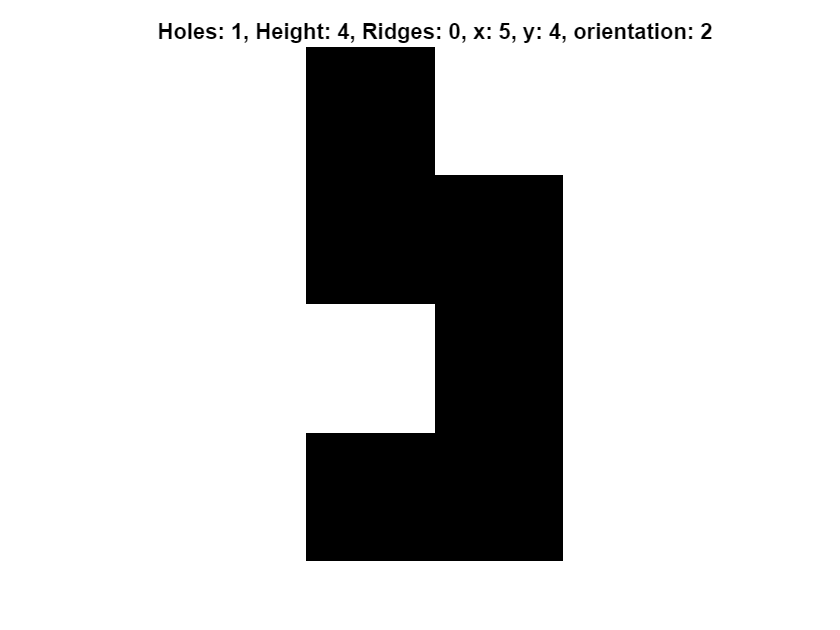

   2   3   2   2   1   1   1   1   0   0

   2   3   2   2   4   3   1   1   0   0



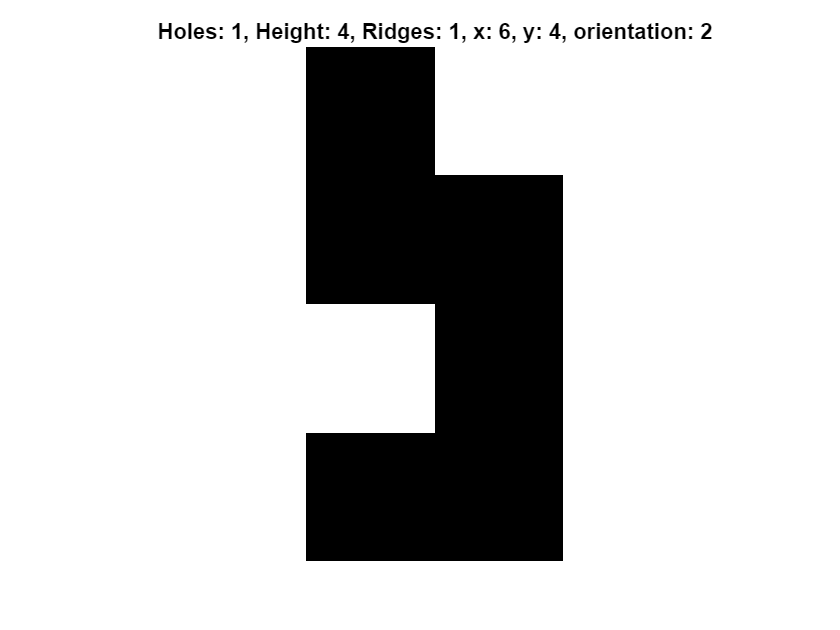

   2   3   2   2   1   1   1   1   0   0

   2   3   2   2   1   4   3   1   0   0



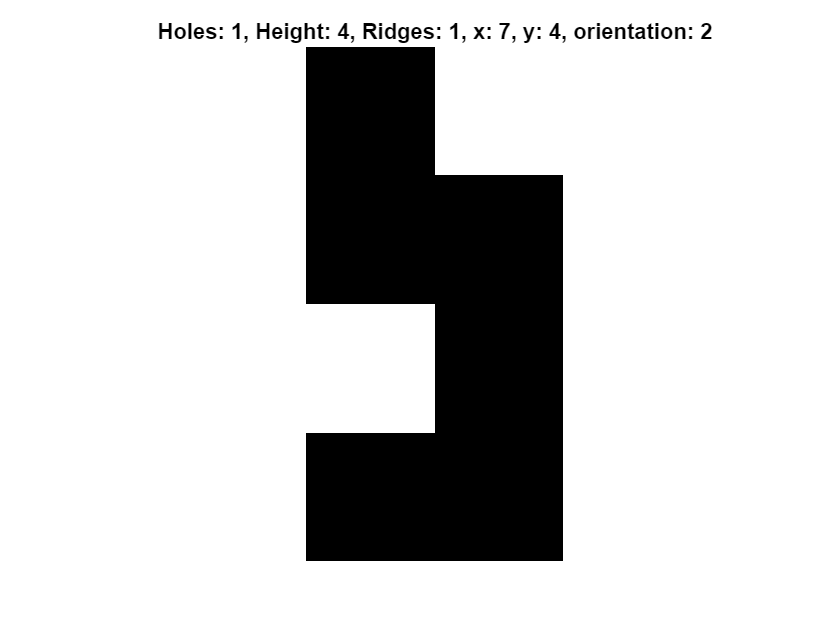

   2   3   2   2   1   1   1   1   0   0

   2   3   2   2   1   1   4   3   0   0



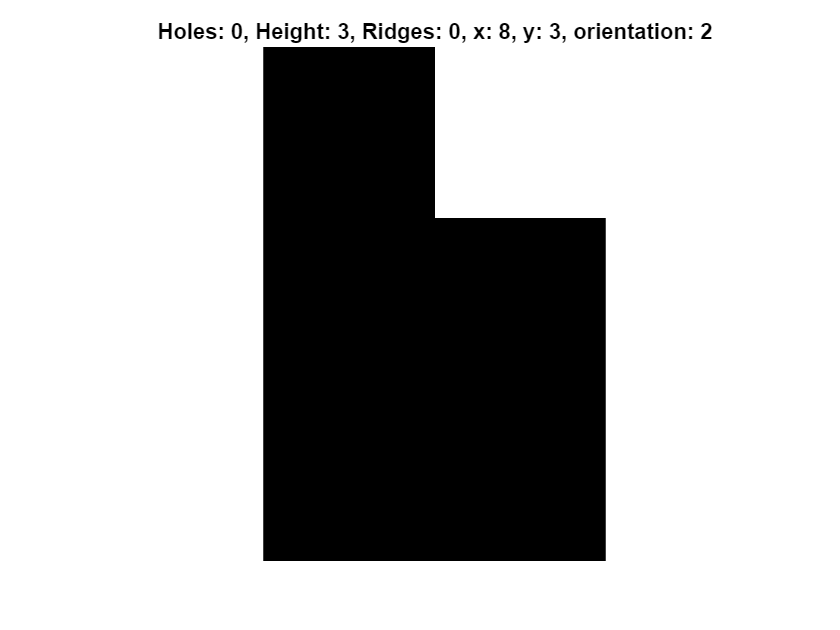

   2   3   2   2   1   1   1   1   0   0

   2   3   2   2   1   1   1   3   2   0



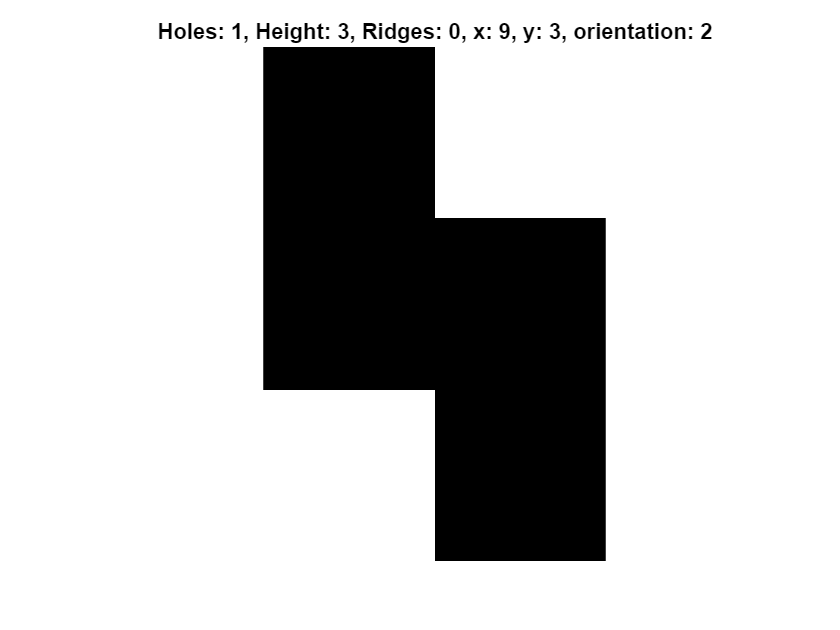

   2   3   2   2   1   1   1   1   0   0

   2   3   2   2   1   1   1   1   3   2



% Solver Based on Tetris State
sv = solver(true);

% Shows All Possible Locations First
% All Regions for the pieces and them being put into there locations. Below
% that will be the previous height map and new height map. The title will
% contain position and all three score criteria.
[endPosition, holdPiece] = sv.solve(s);


disp("Hold the Piece"); disp(holdPiece);

Hold the Piece
   0



disp("End Positon (x, y, o): "); disp(endPosition);

End Positon (x, y, o): 
   7   2   3



actionsList = actions.GetActionsList(endPosition, s.piece, holdPiece);
disp("Actions to Perform: "); disp(actionsList);

Actions to Perform: 
    rotate    rotate    right     right     right     drop  

